# **part one**

## **a**

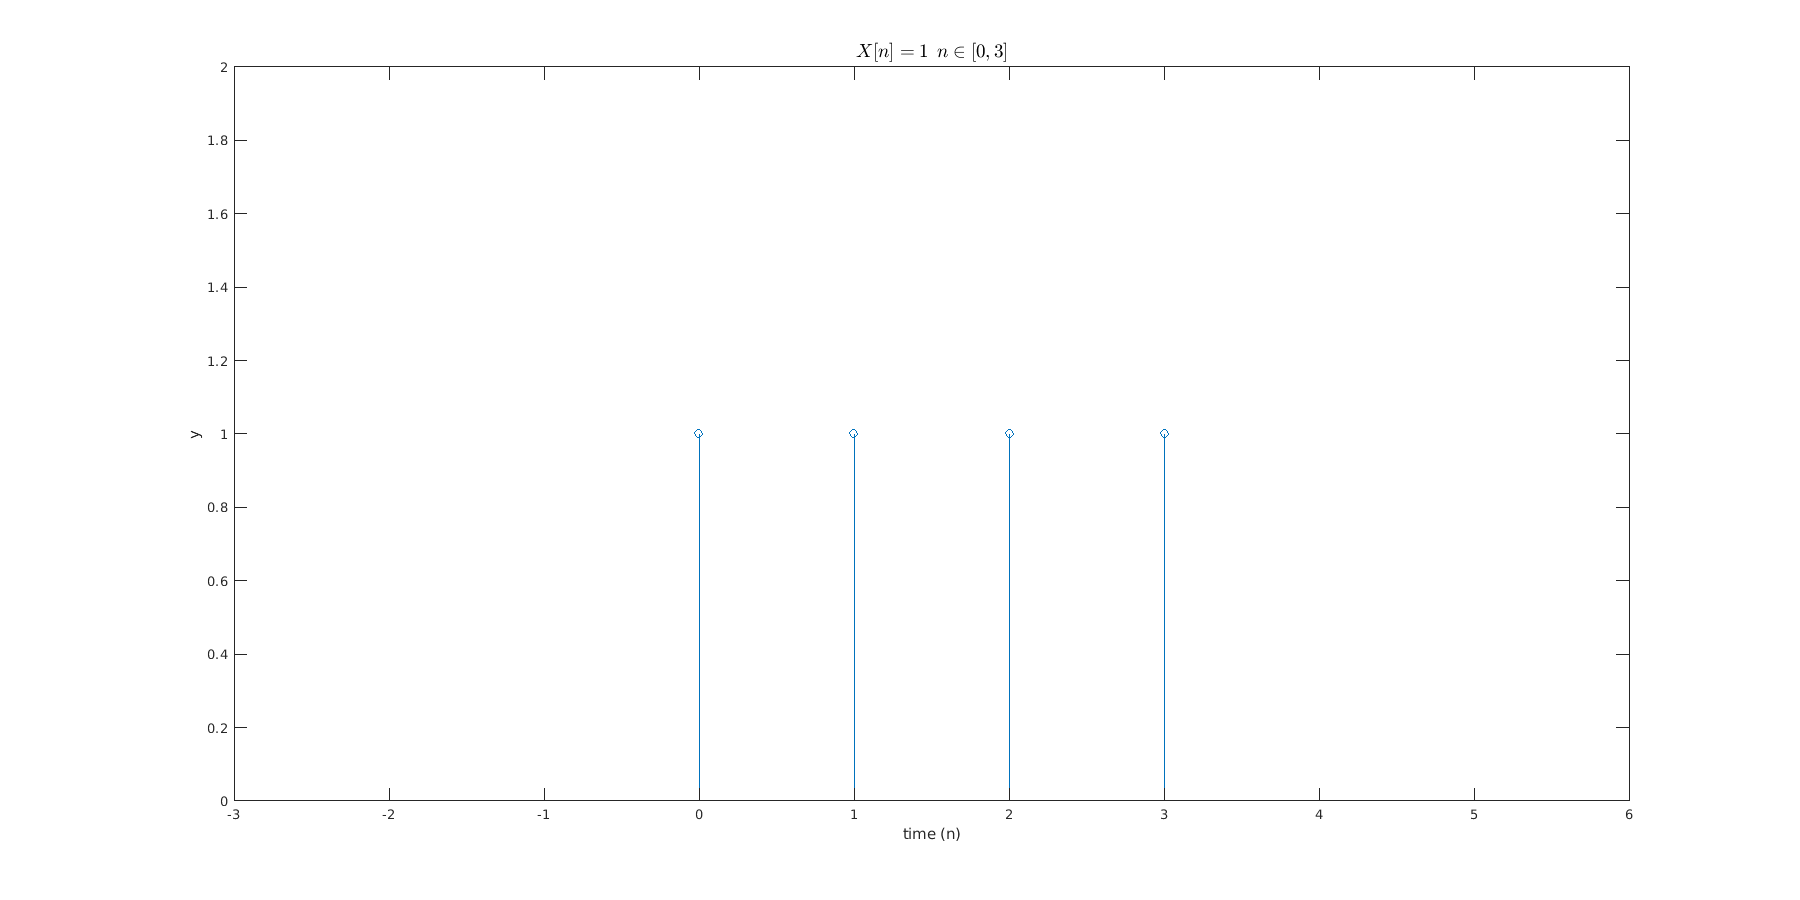

x1 = @(t) 1 .* (t==1 | t == 2 | t == 3 | t == 0);
clear title;
time_step_1 =1;
t_1 = 0:time_step_1:3;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs_1 = 1/time_step_1;
stem(t_1,x1(t_1));
ylim([0,2]);
xlim([-3,6])
shg;
xlabel('time (n)');
title('$ X[n] = 1 \: \: n \in  [0,3]$',"fontsize",14,"interpreter","latex");
ylabel('y');

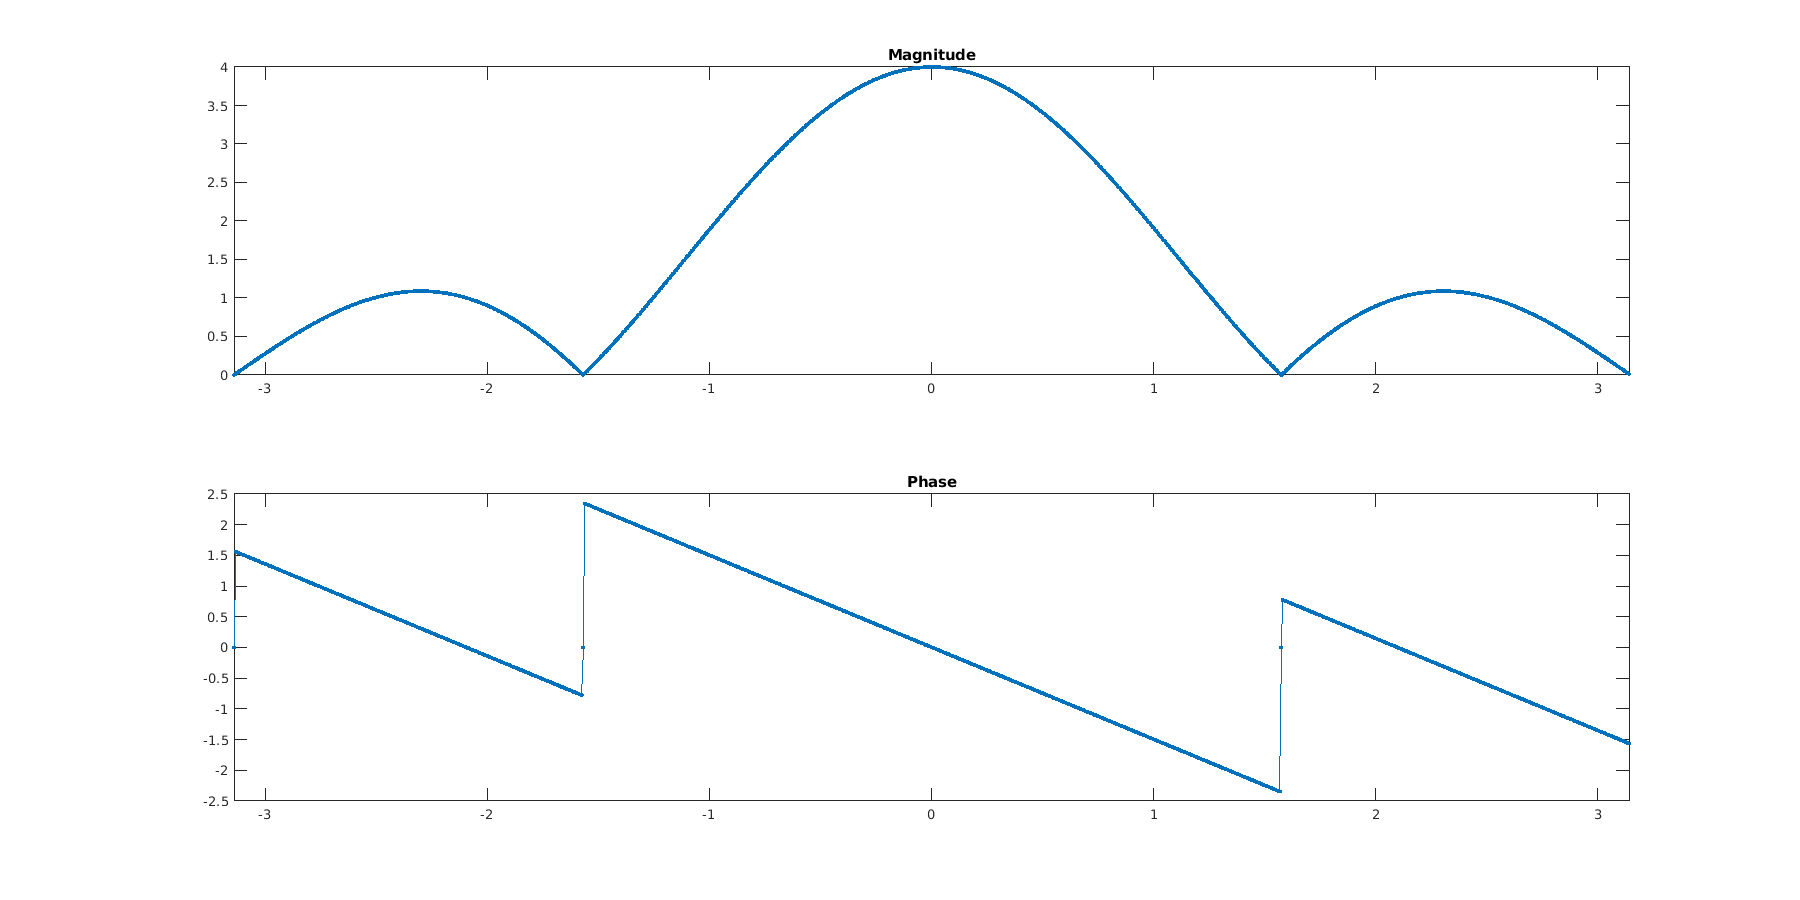


abs_f = @(x) abs(x);
yfft = fftshift(fft(x1(t_1),1024));
f = linspace(-pi, pi, numel(yfft));
fft_plot_abs(f,yfft,[-pi,pi],[-pi,pi]);

## b

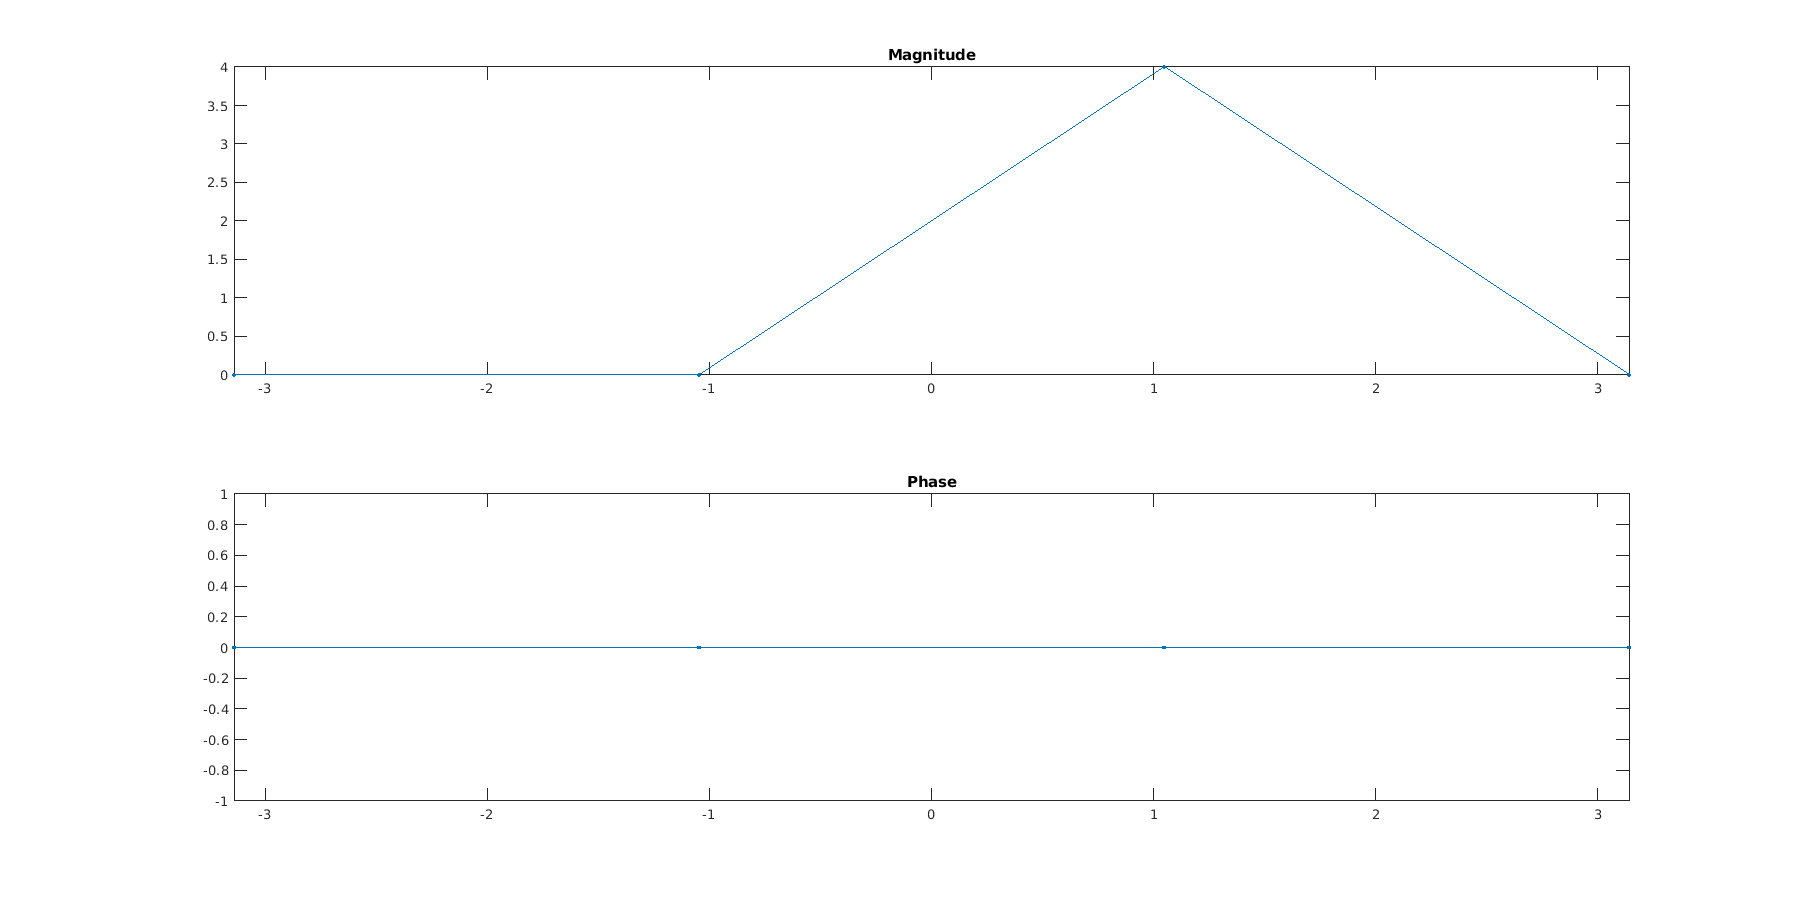


yfft = fftshift(fft(x1(t_1)));
f = linspace(-pi, pi, numel(yfft));
fft_plot_abs(f,yfft,[-pi,pi],[-pi,pi]);

## c

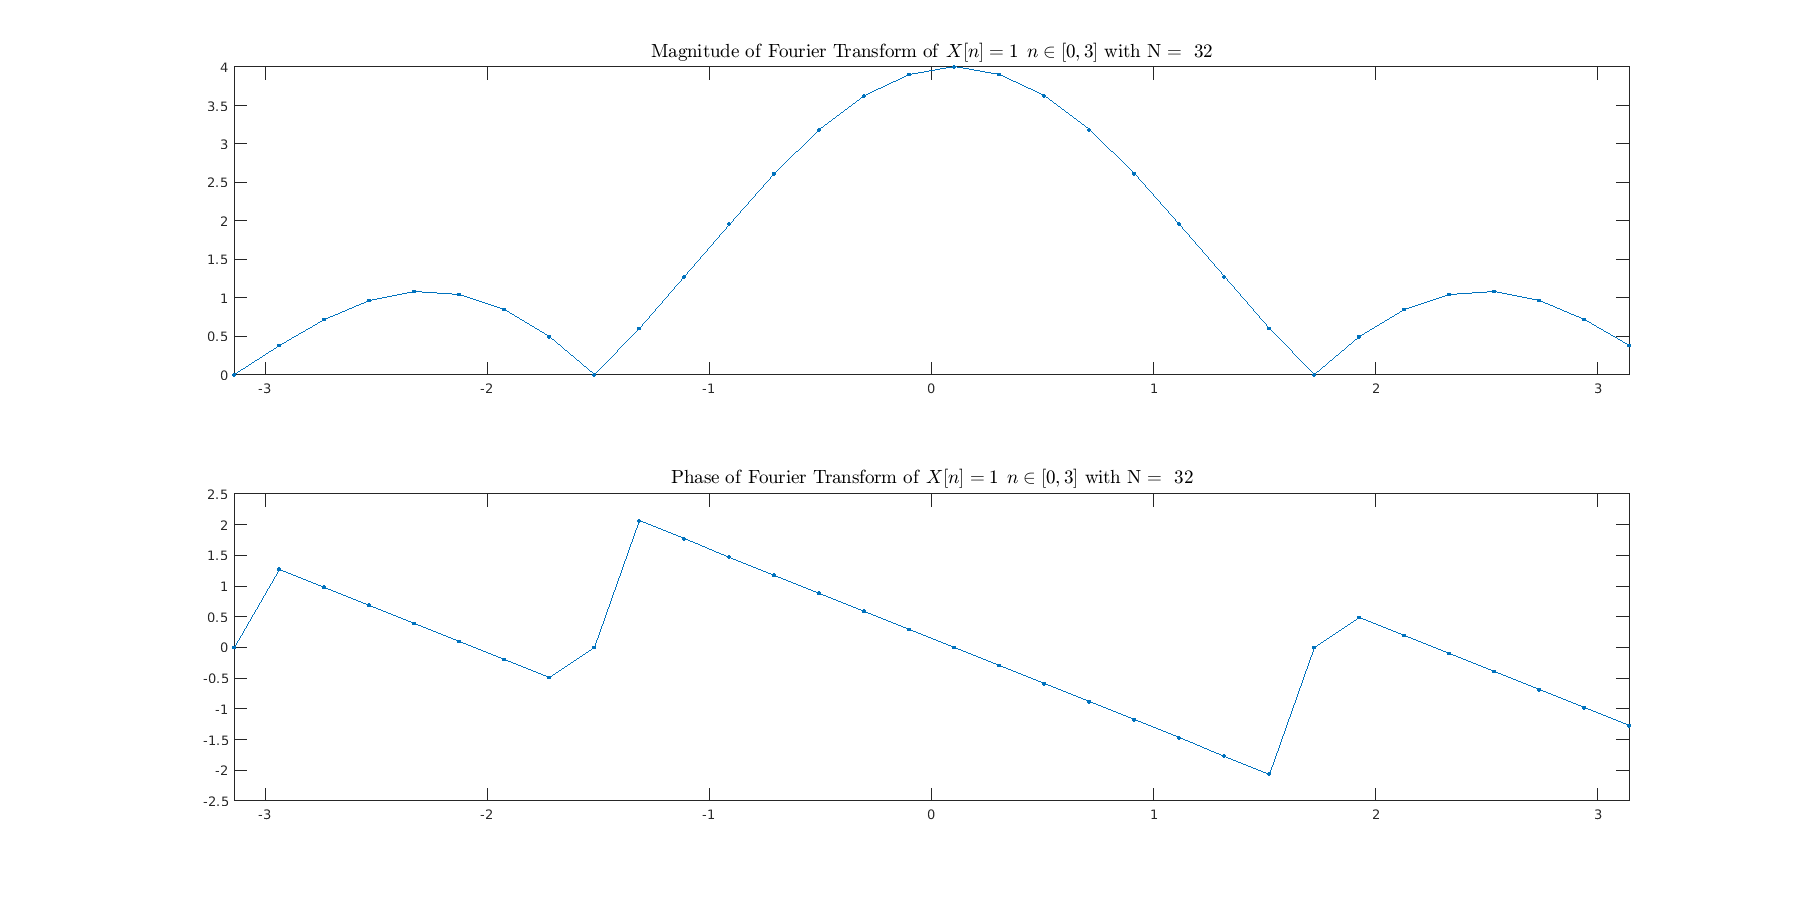

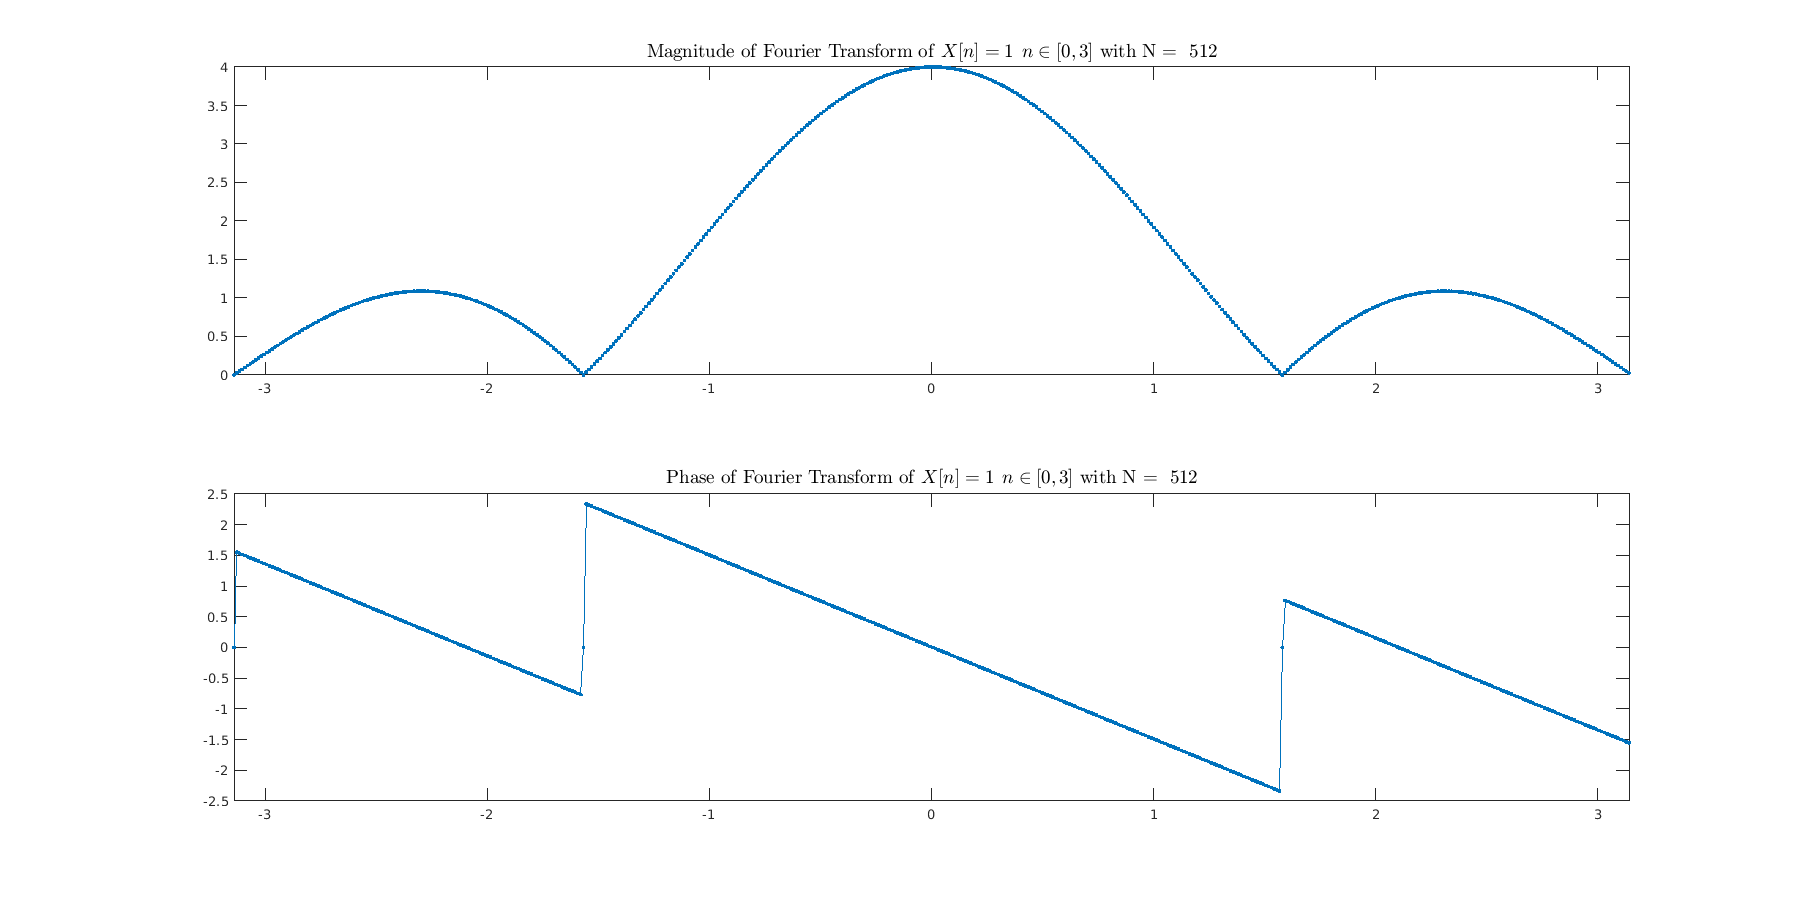

% by changing n we can obtain other DFT
fft_repeat_plot_abs(x1(t_1),[32,512]," $ X[n] = 1 \: \: n \in  [0,3] $ ")

# Part two

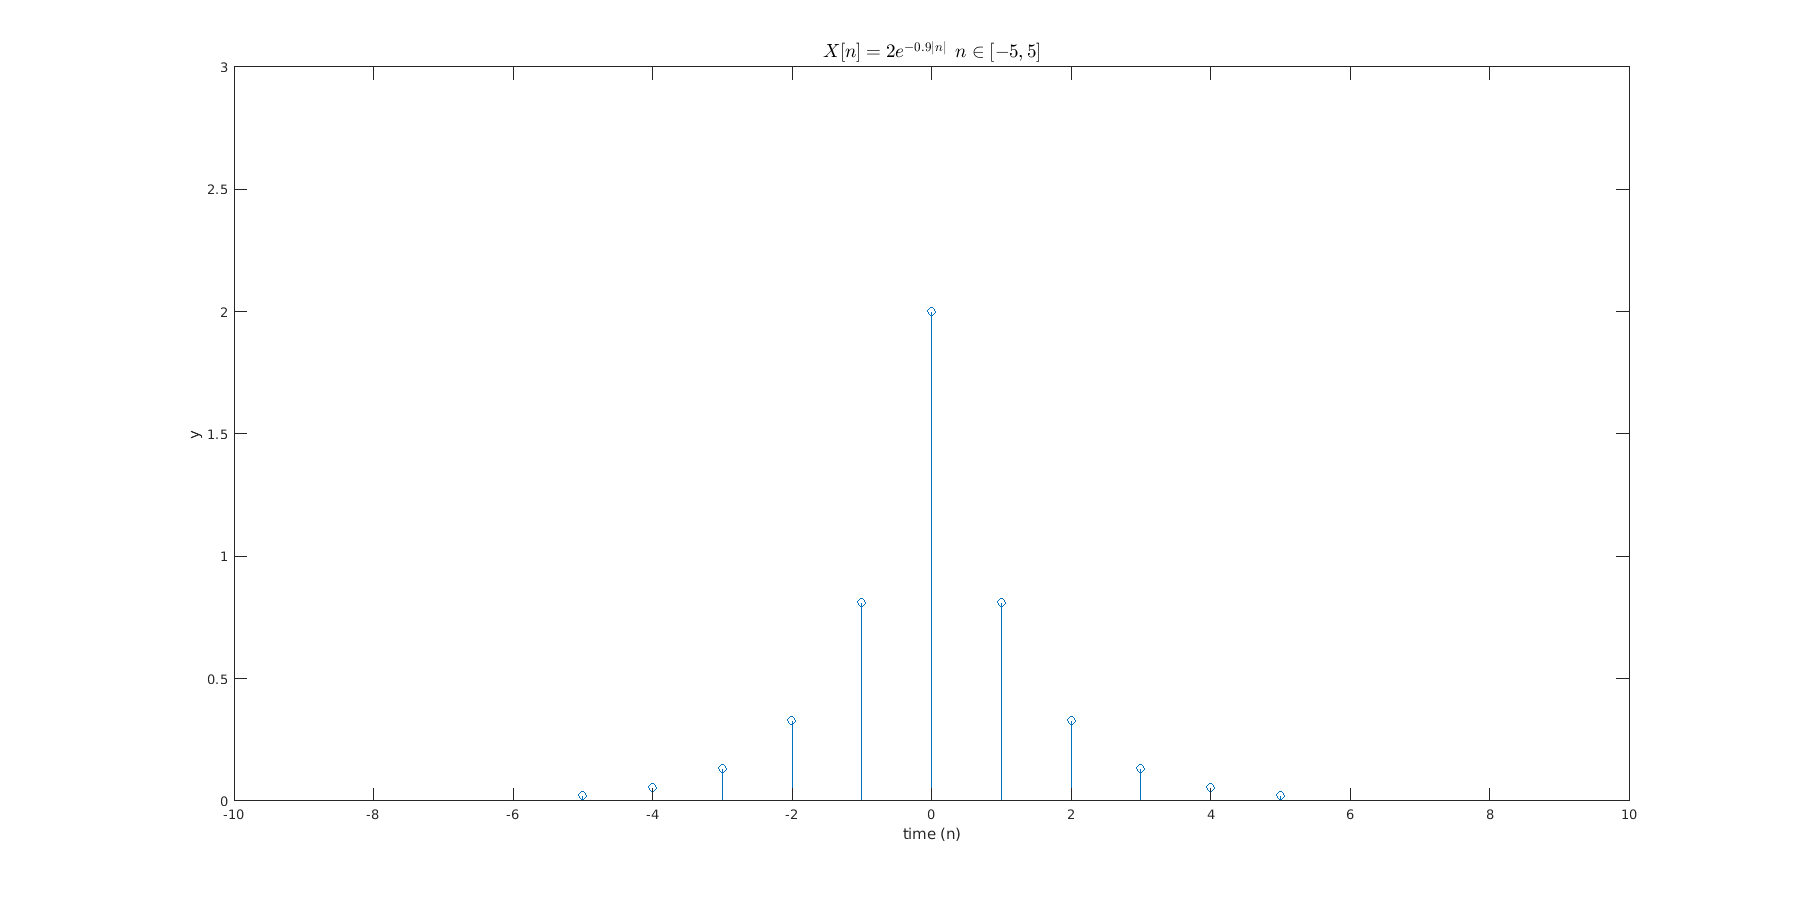

x = @(t) 2*exp(-0.9 .* abs(t)).* ((t<= 5) & (t>= -5));
clear title;
time_step =1;
t = -5:time_step:5;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1/time_step;
stem(t,x(t));
ylim([0,3]);
xlim([-10,10])
shg;
xlabel('time (n)');
title('$ X[n] = 2e^{-0.9 |n|} \: \: n \in  [-5,5]$',"fontsize",14,"interpreter","latex");
ylabel('y');

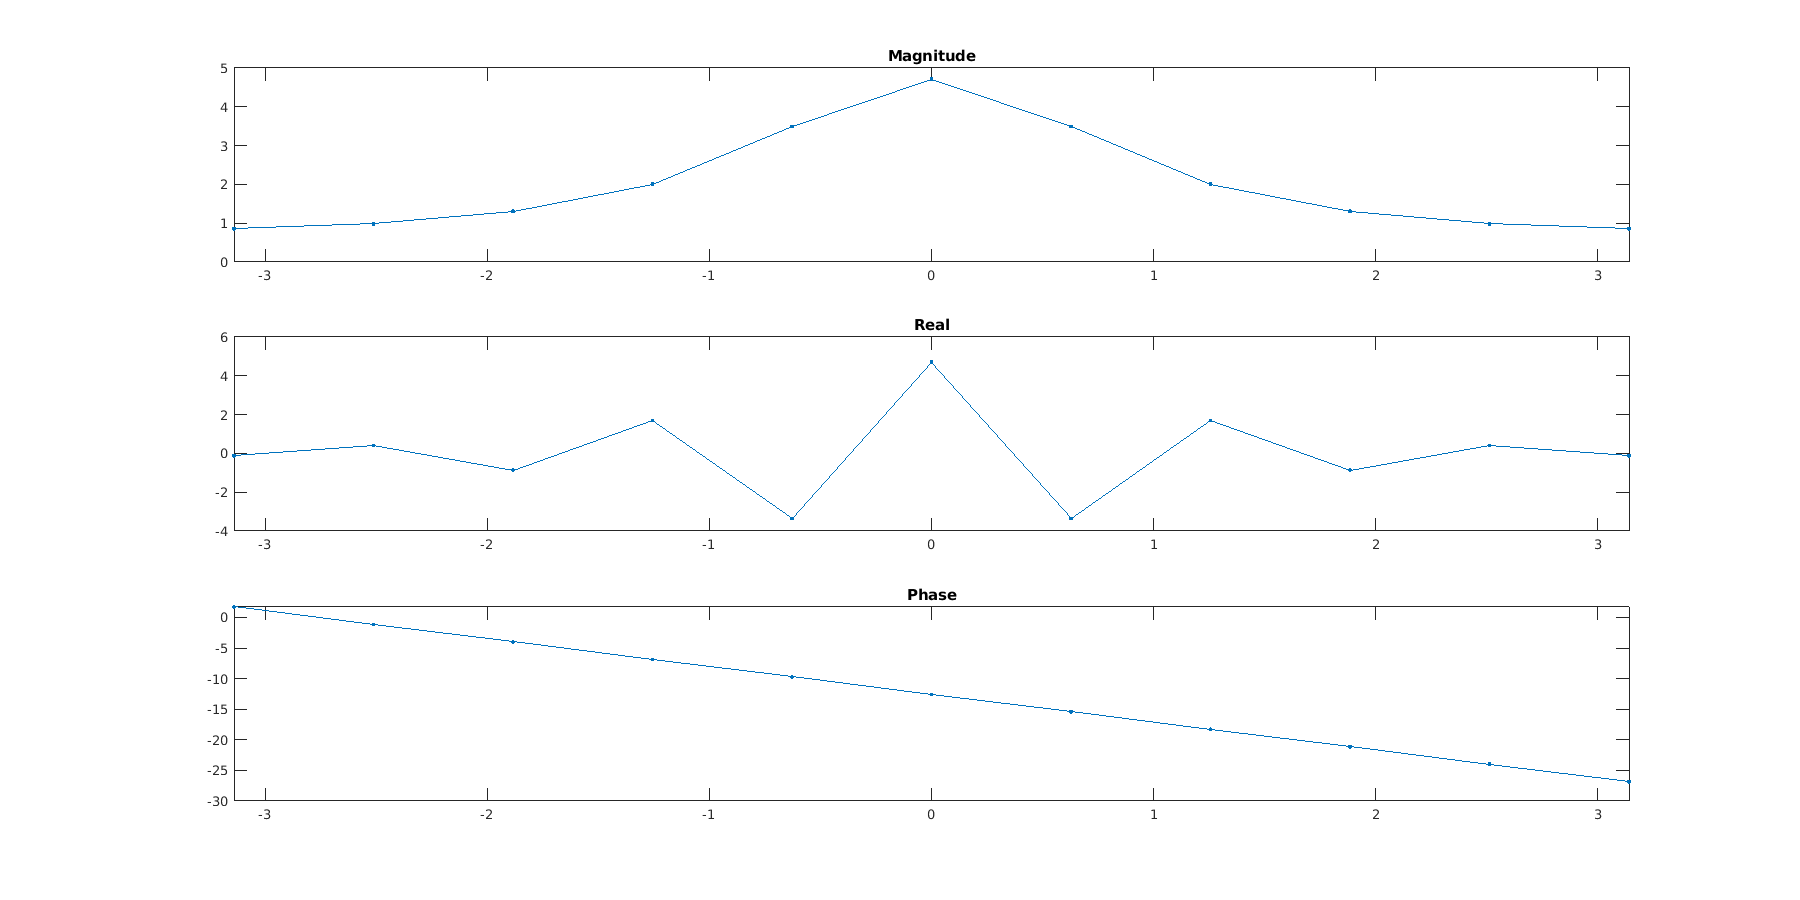

yfft = fftshift(fft(x(t)));
f = linspace(-pi, pi, numel(yfft));
fft_plot(f,yfft,[-pi,pi],[-pi,pi]);

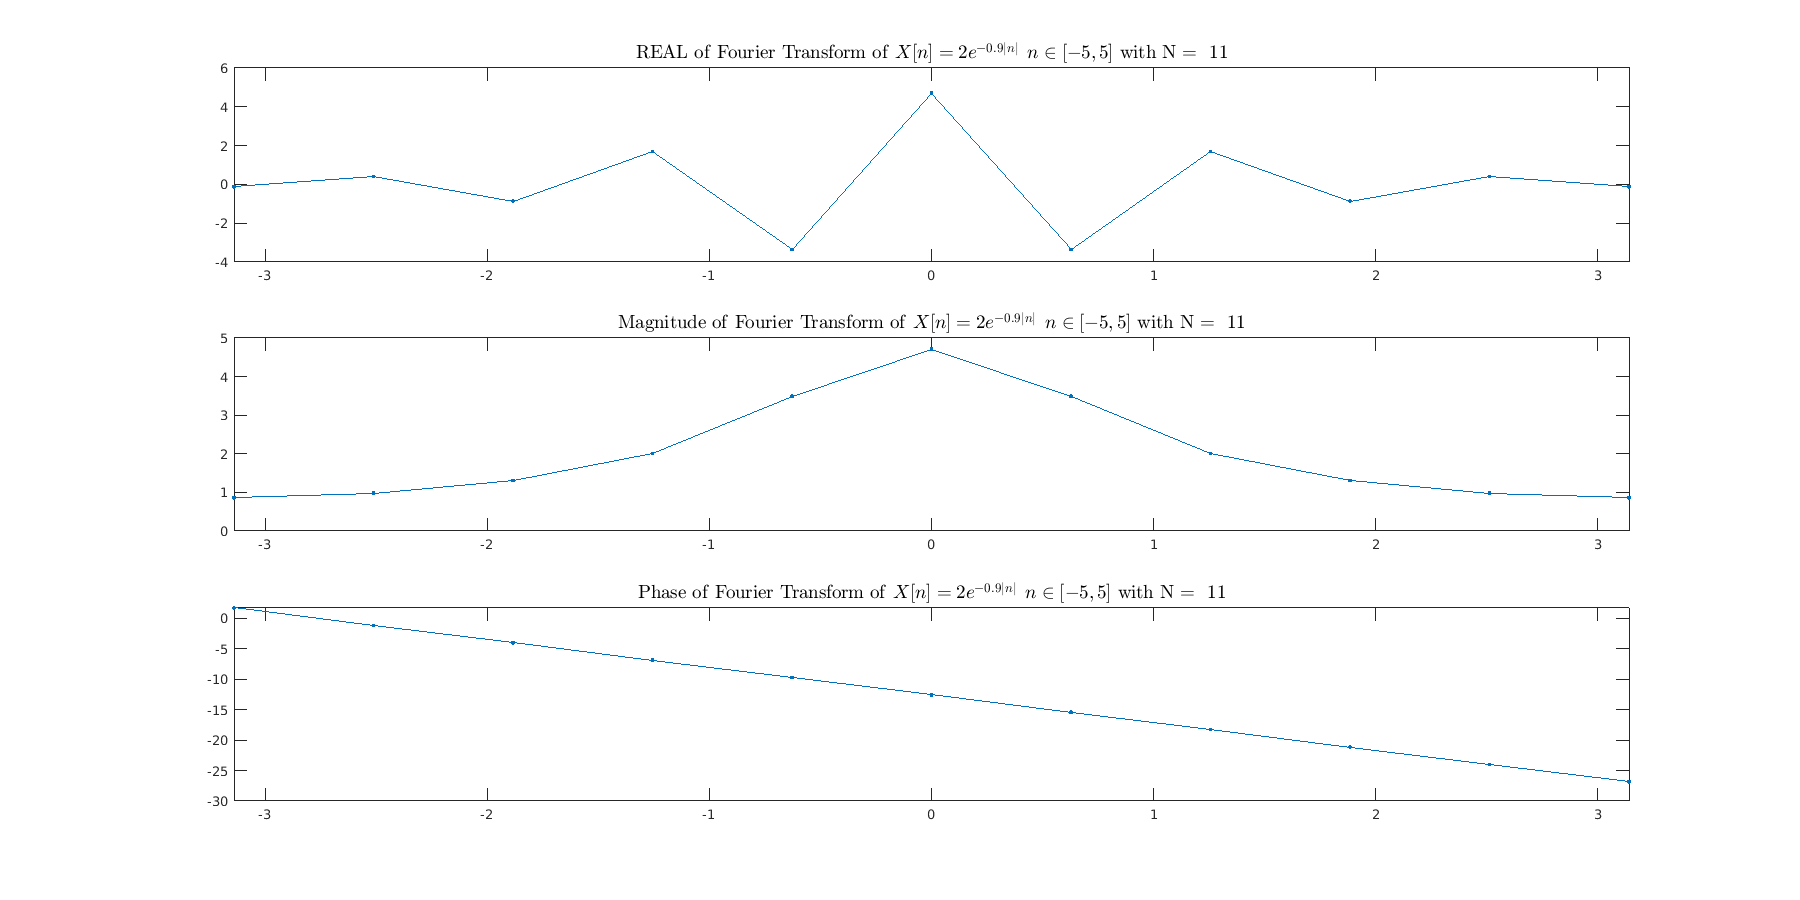

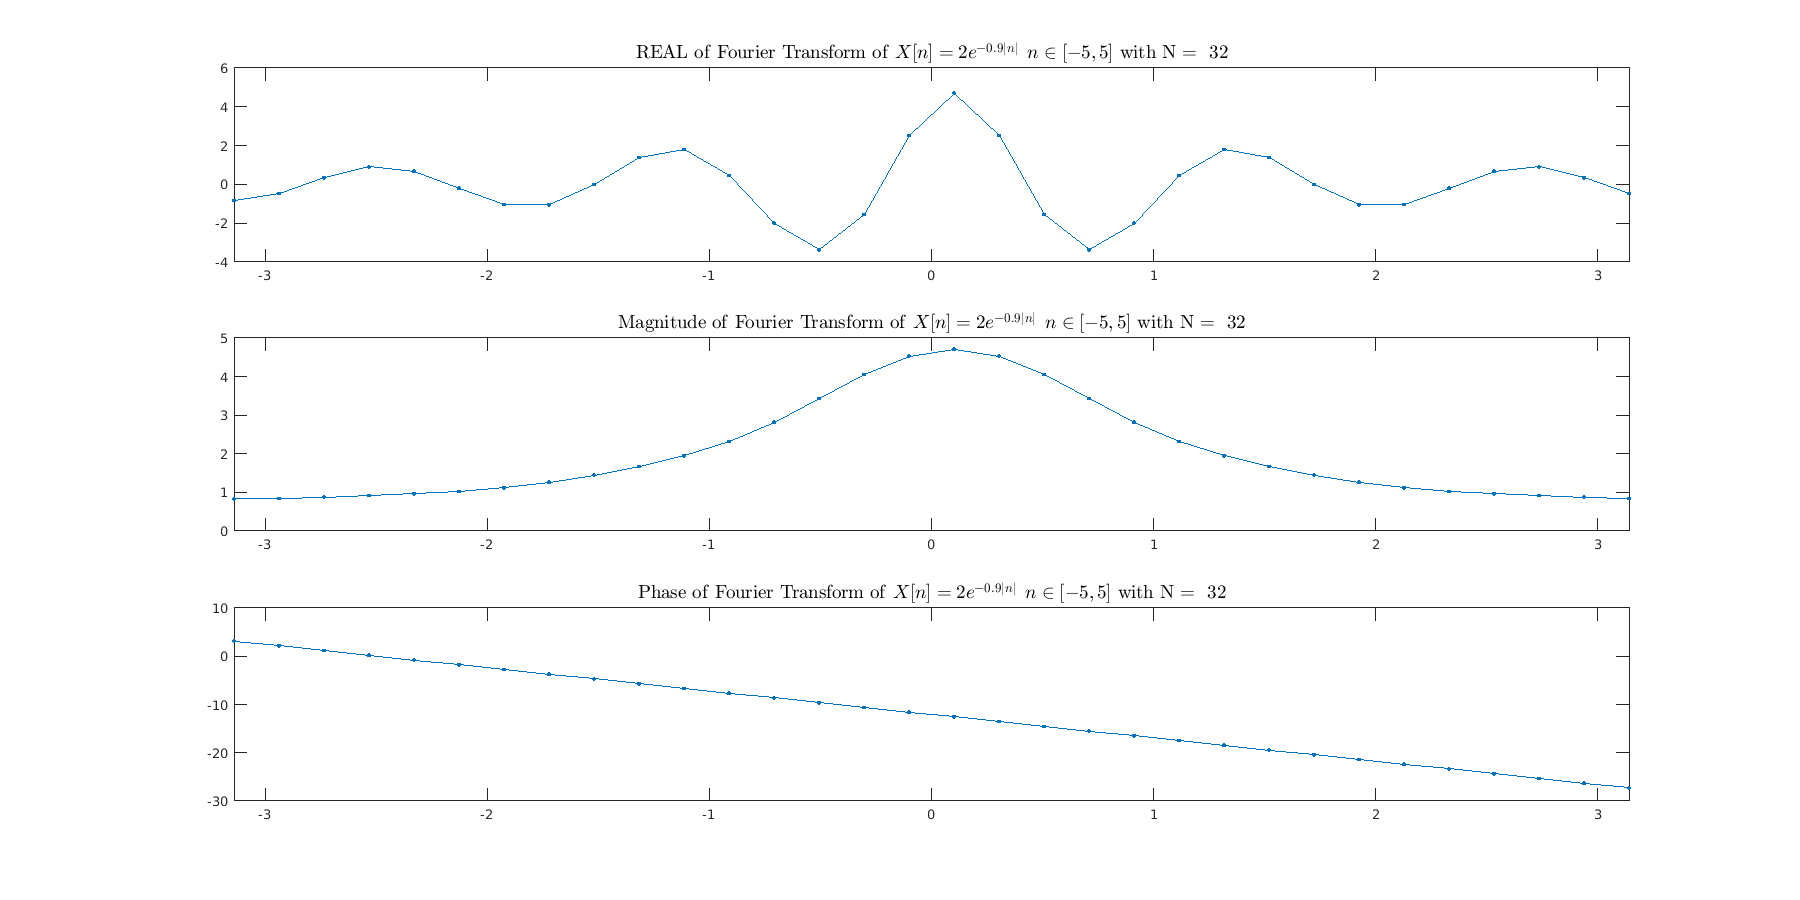

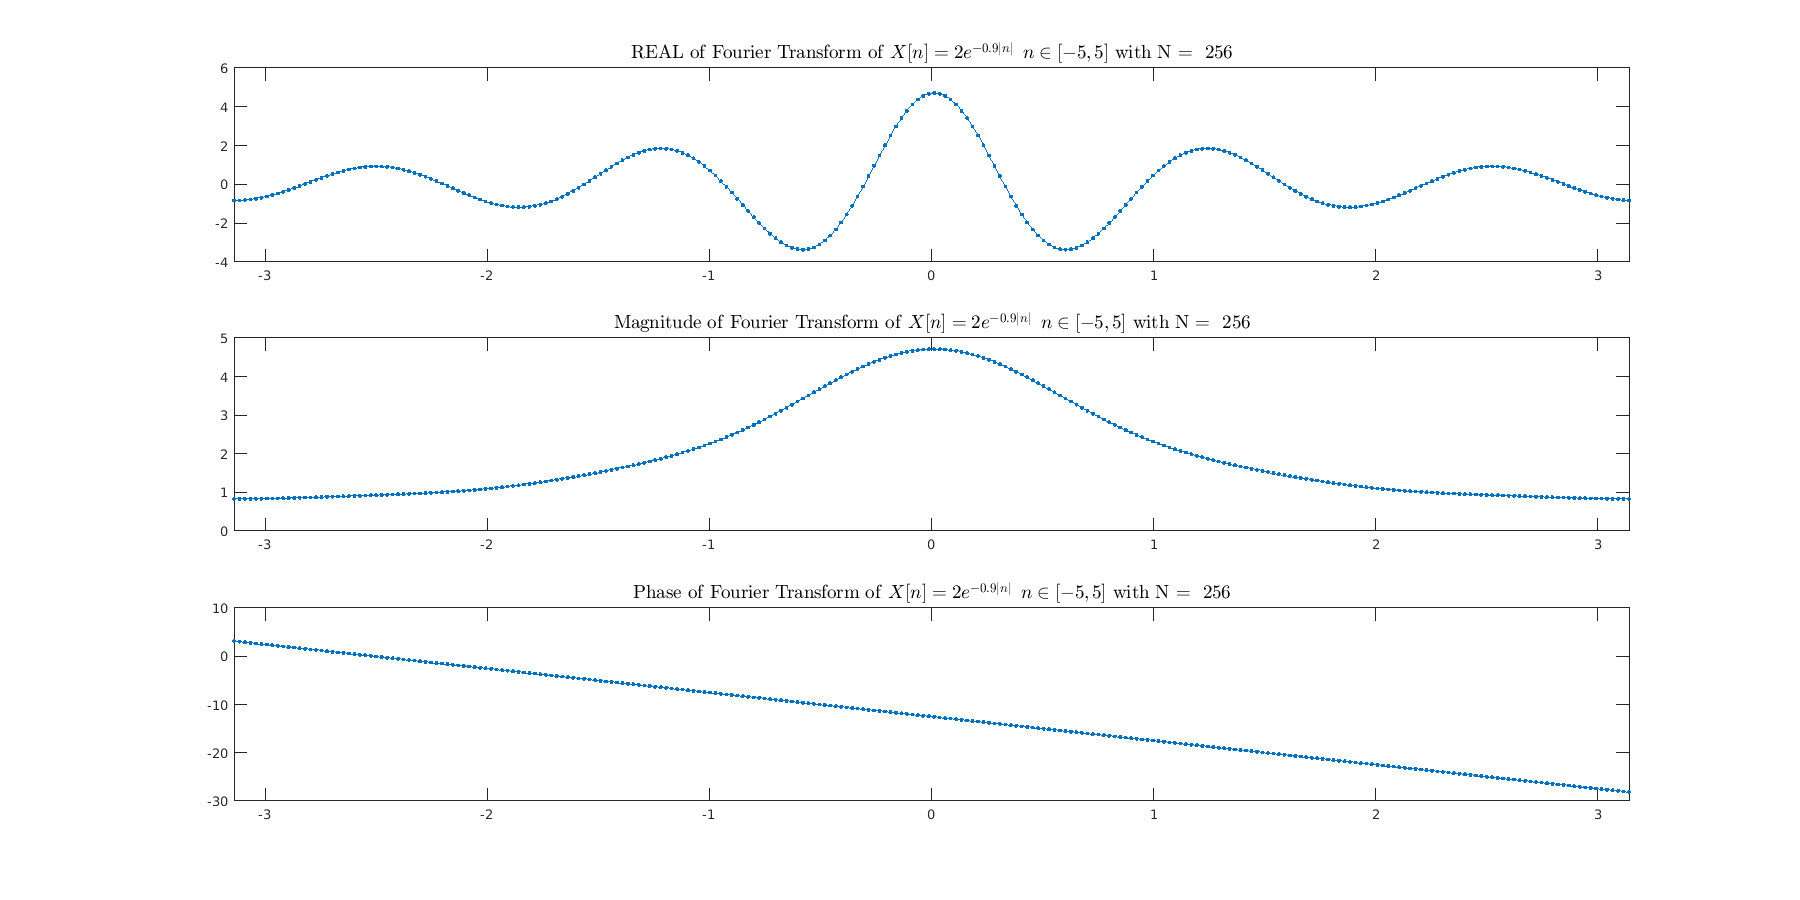


fft_repeat_plot(x(t),[11,32,256]," $ X[n] = 2e^{-0.9 |n|} \: \: n \in  [-5,5] $ ")

# Part three

## x1

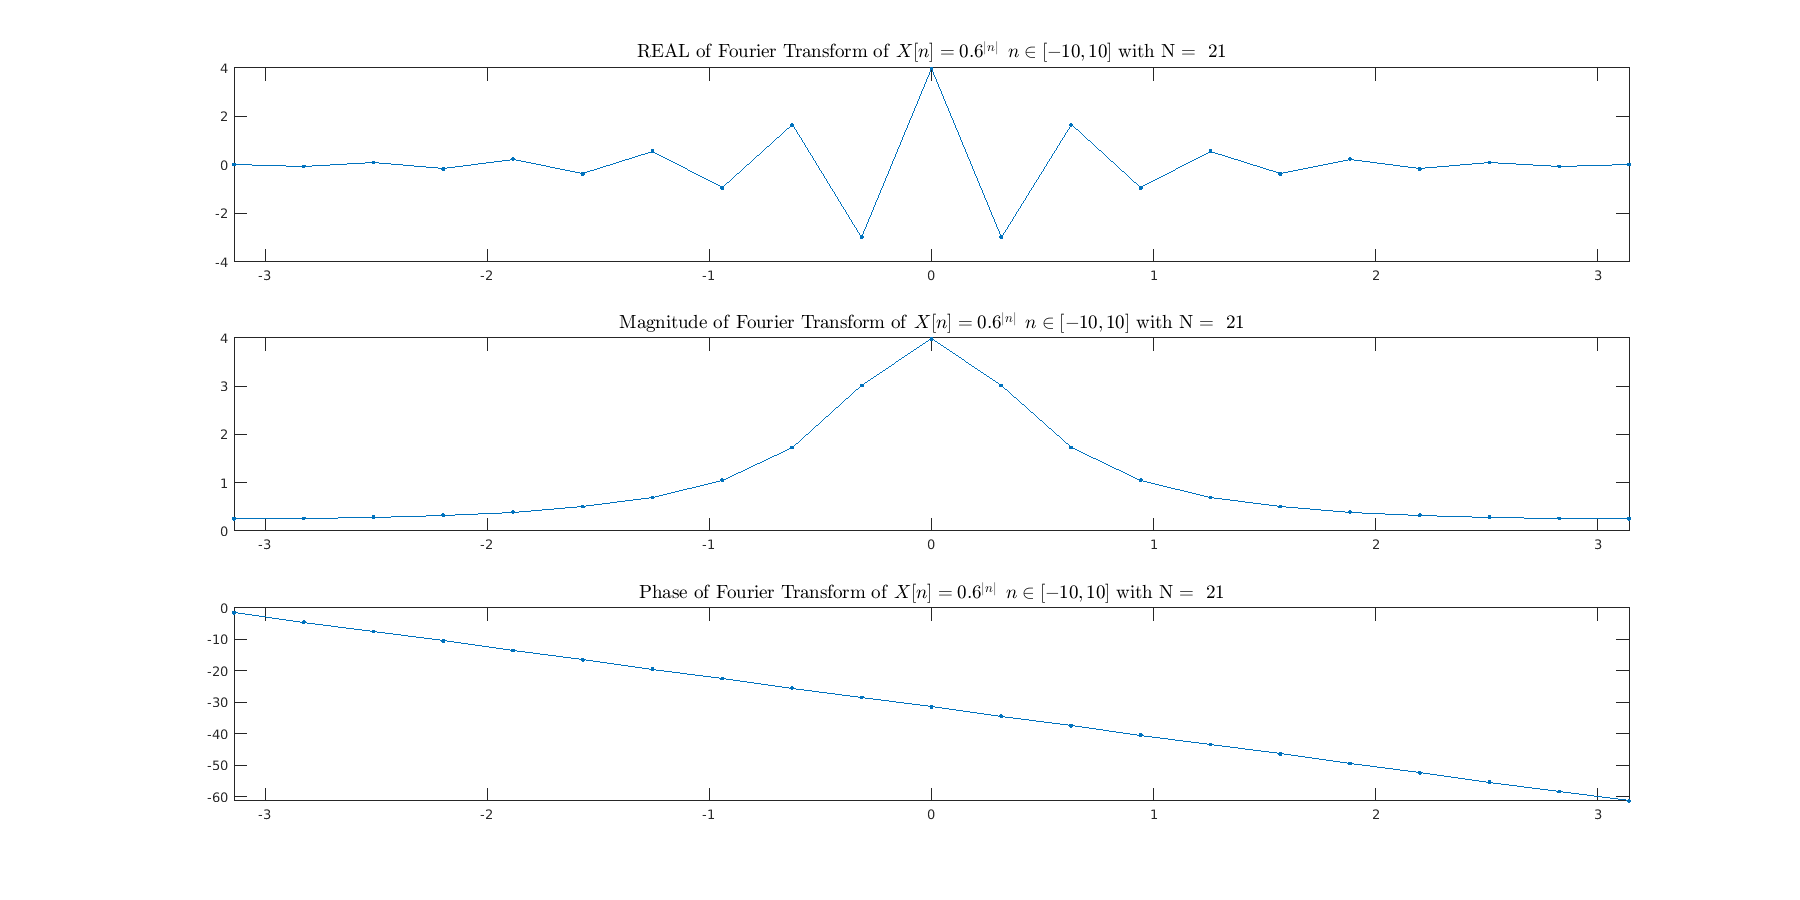

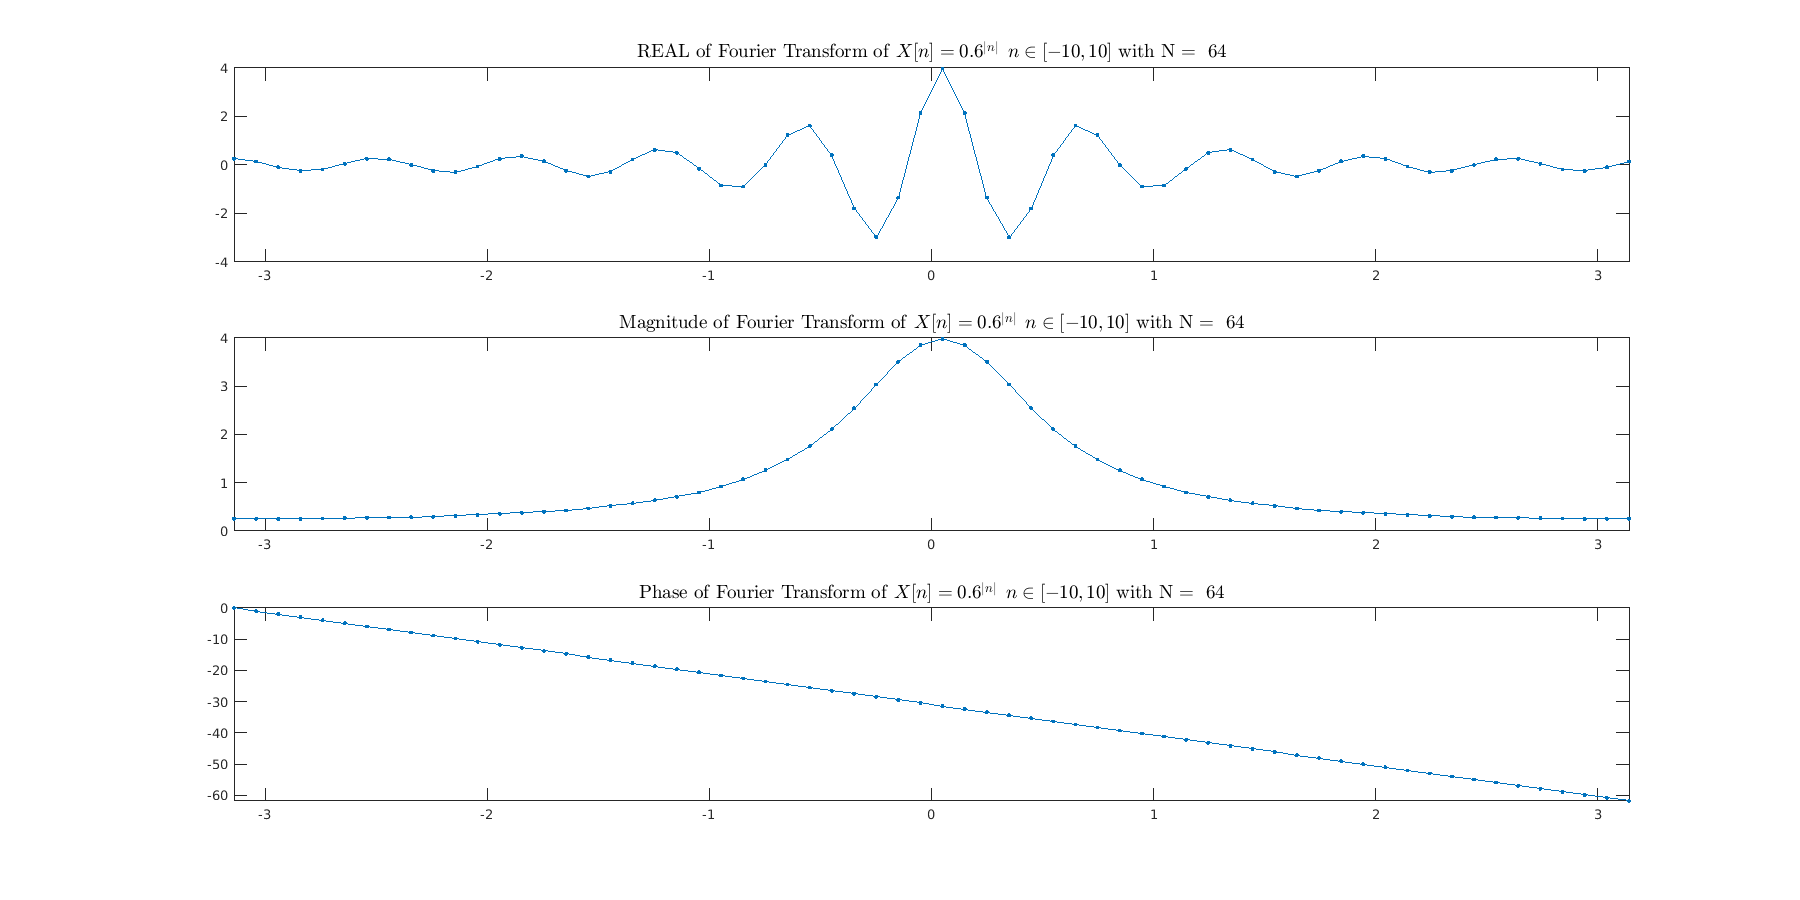

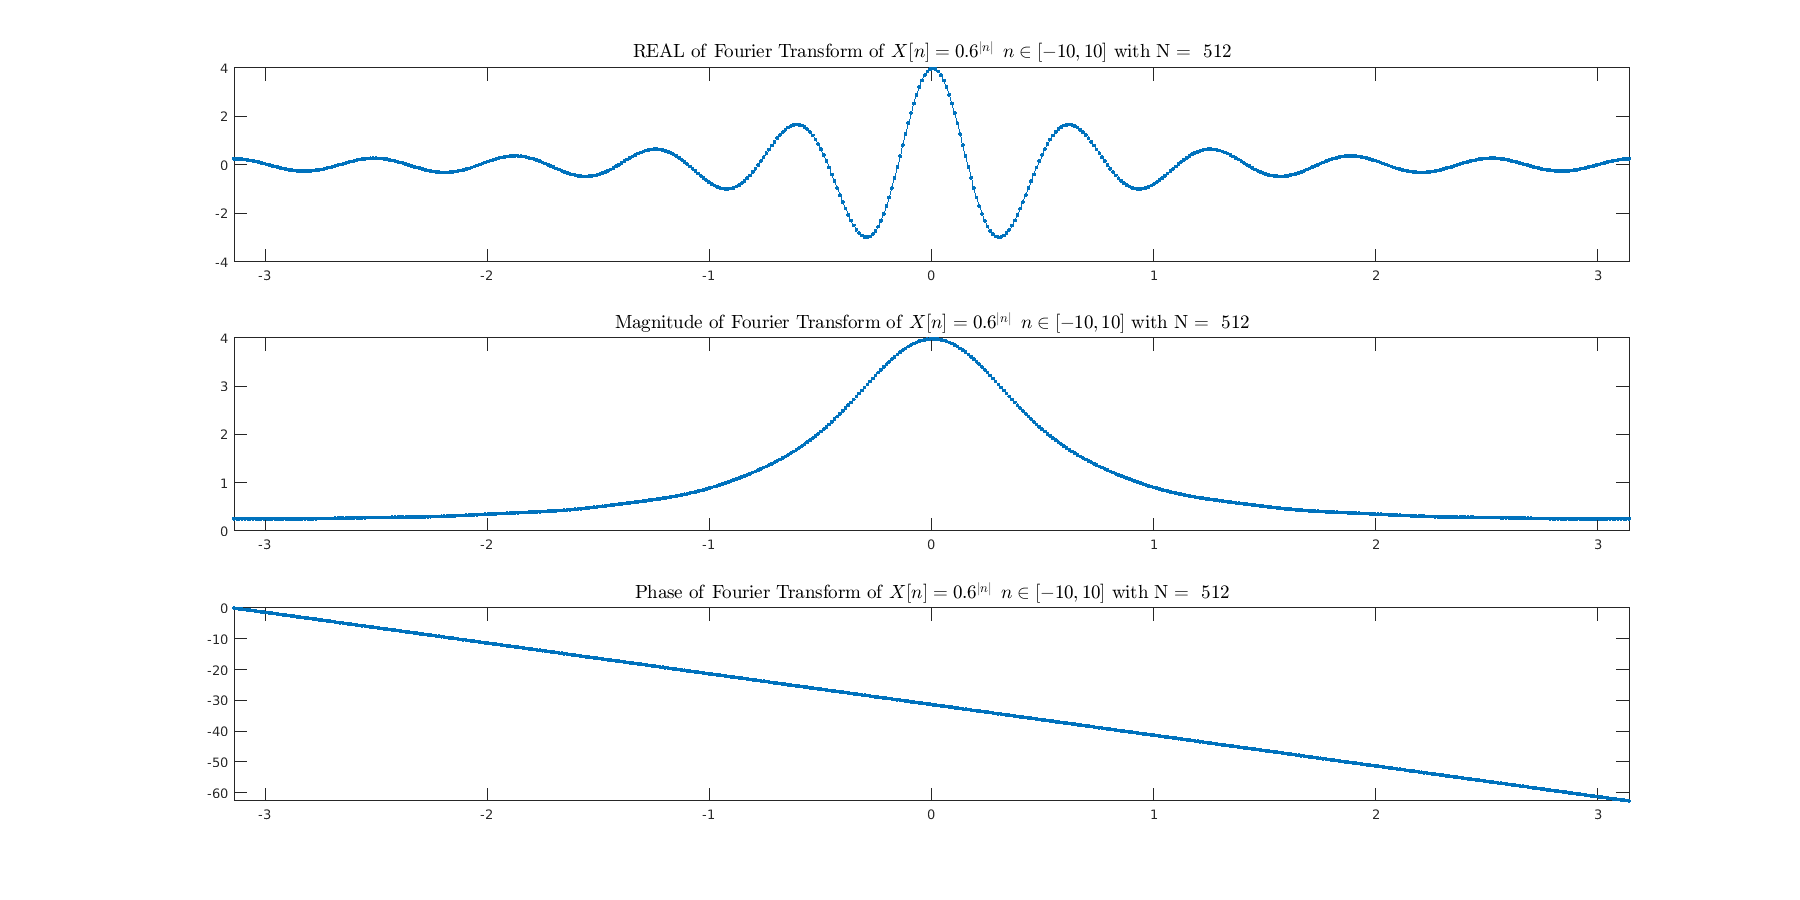

x = @(t) 0.6.^(abs(t)).* ((t<= 10) & (t>= -10));
clear title;
time_step =1;
t = -10:time_step:10;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1/time_step;

fft_repeat_plot(x(t),[21,64,512]," $ X[n] = 0.6^{|n|} \: \: n \in  [-10,10] $ ")

## x2

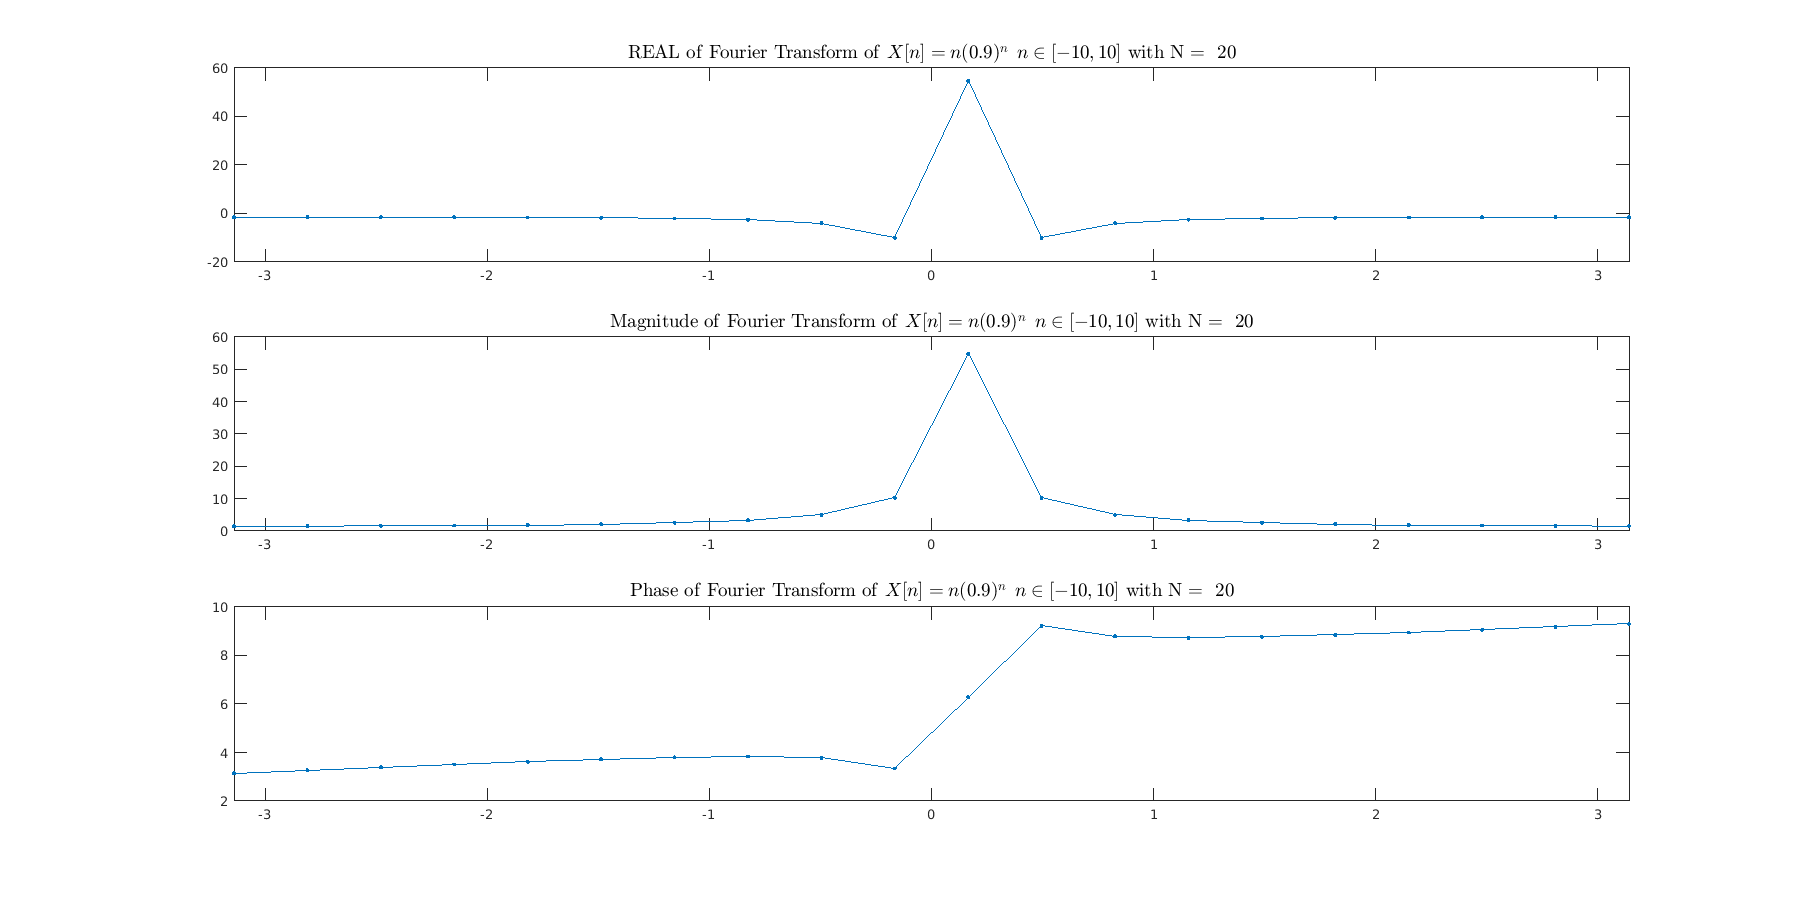

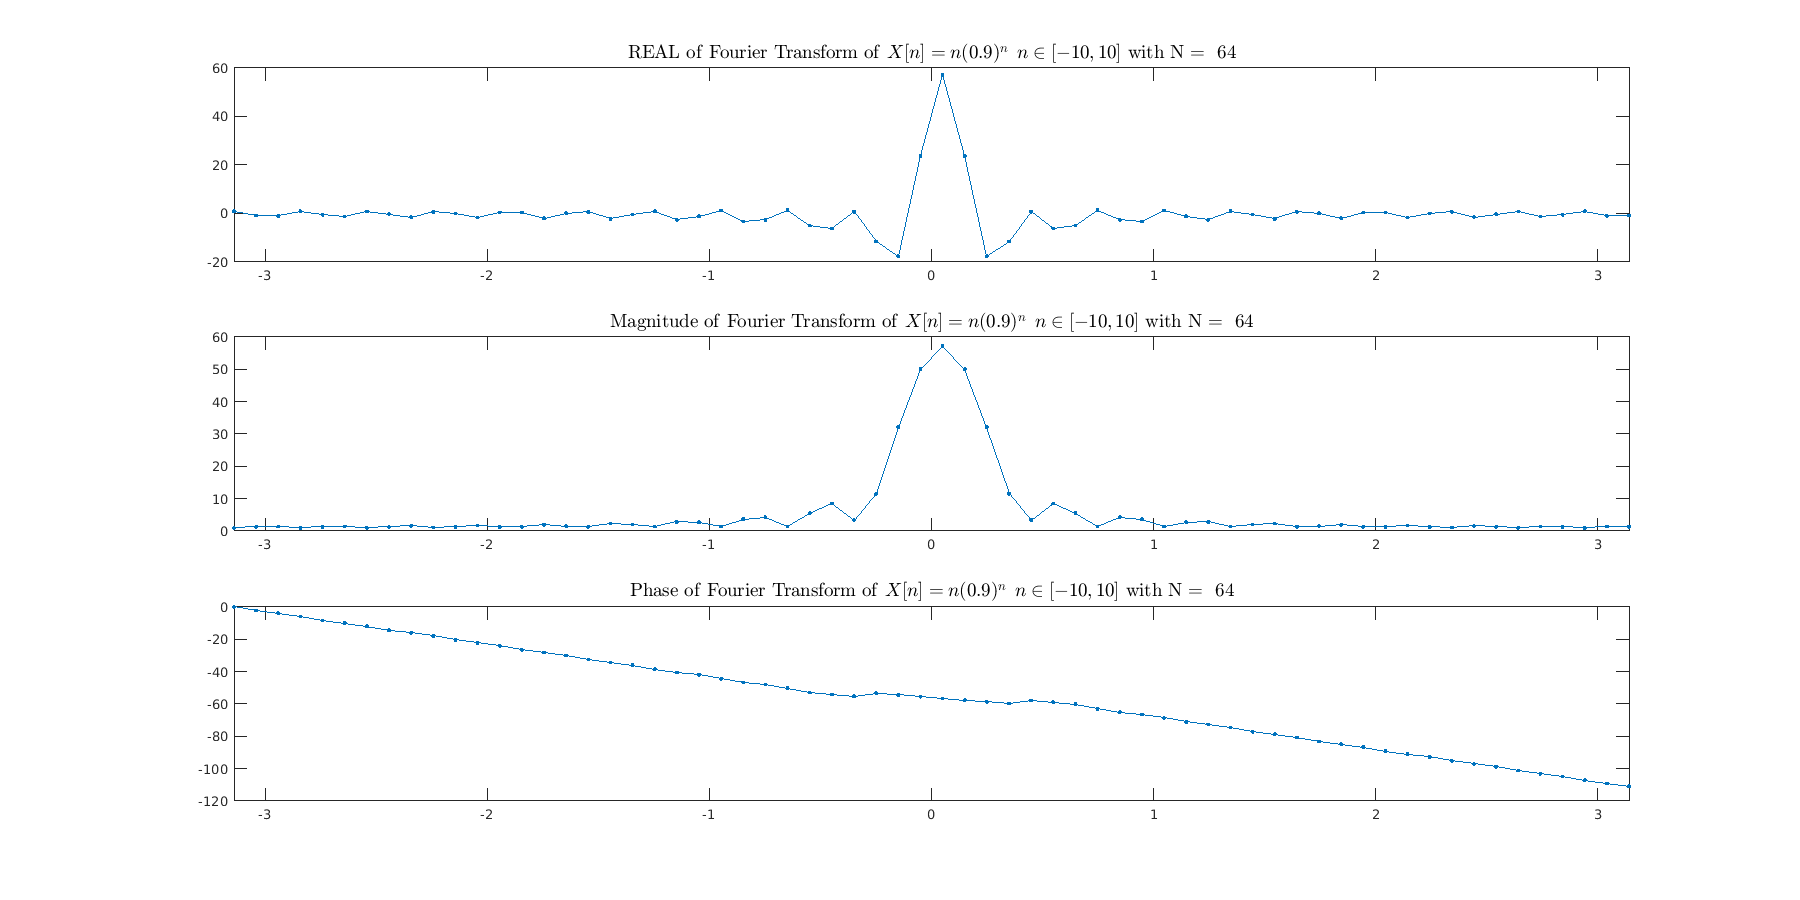

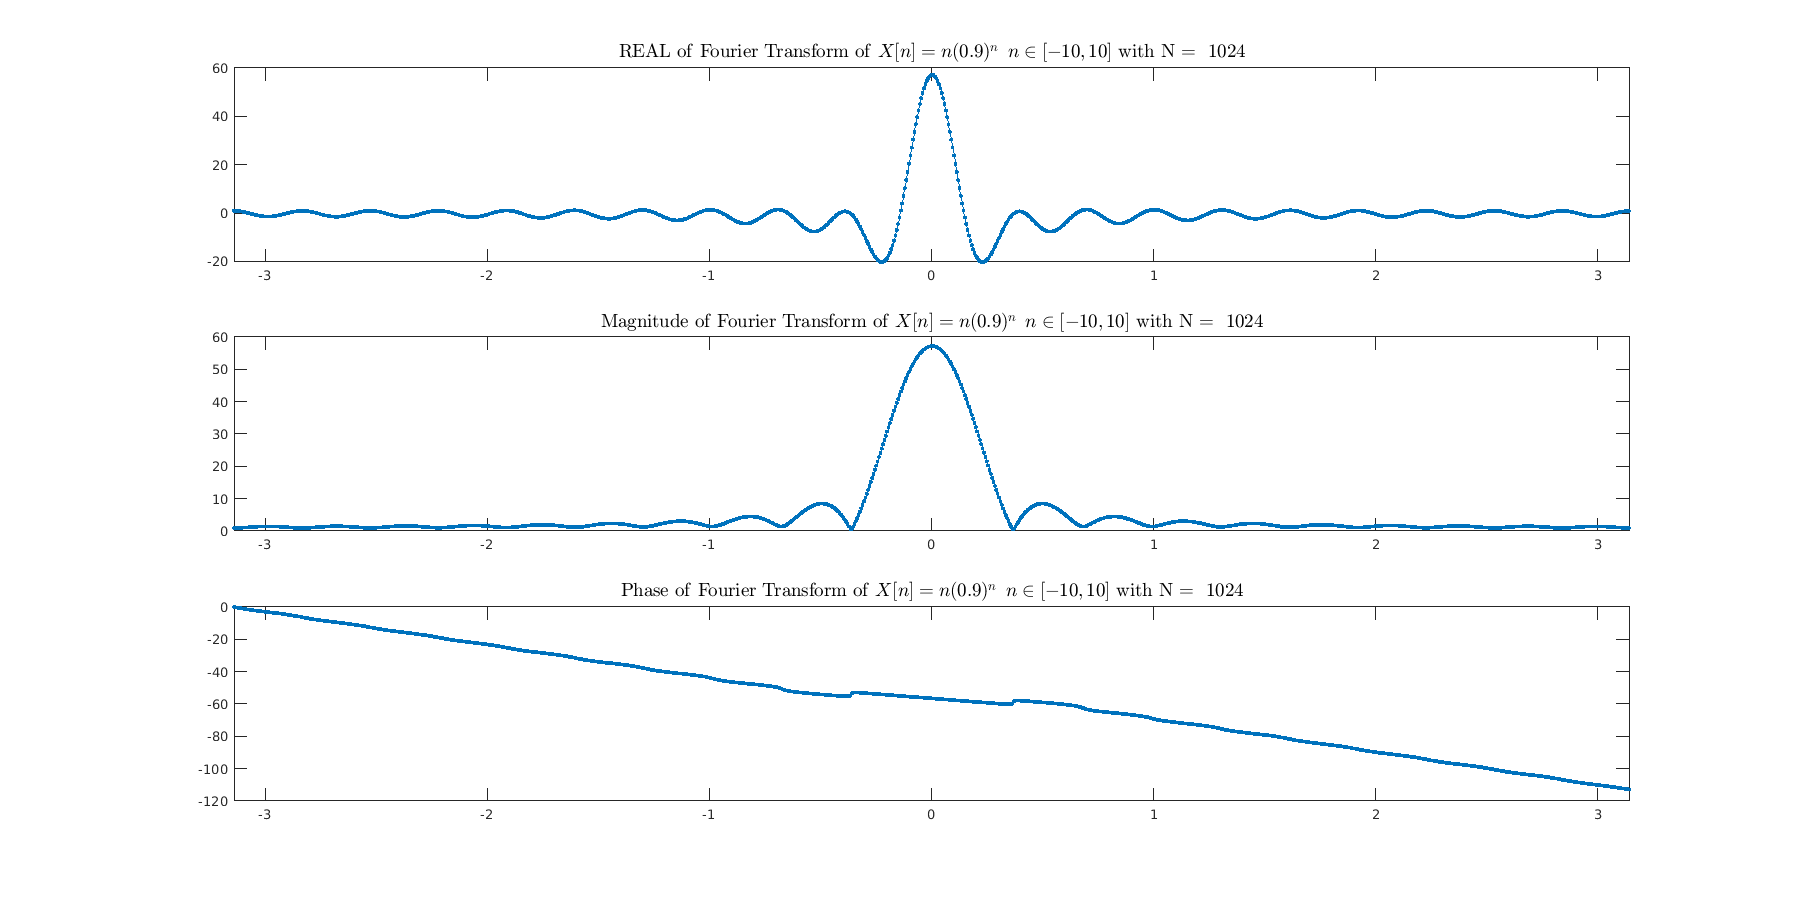

x = @(t) t .*(0.9).^t .* ((t<= 20) & (t>= 0));
clear title;
time_step =1;
t = 0:time_step:20;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1/time_step;
fft_repeat_plot(x(t),[20,64,1024]," $ X[n] = n (0.9)^n \: \: n \in  [-10,10] $ ")

## x3

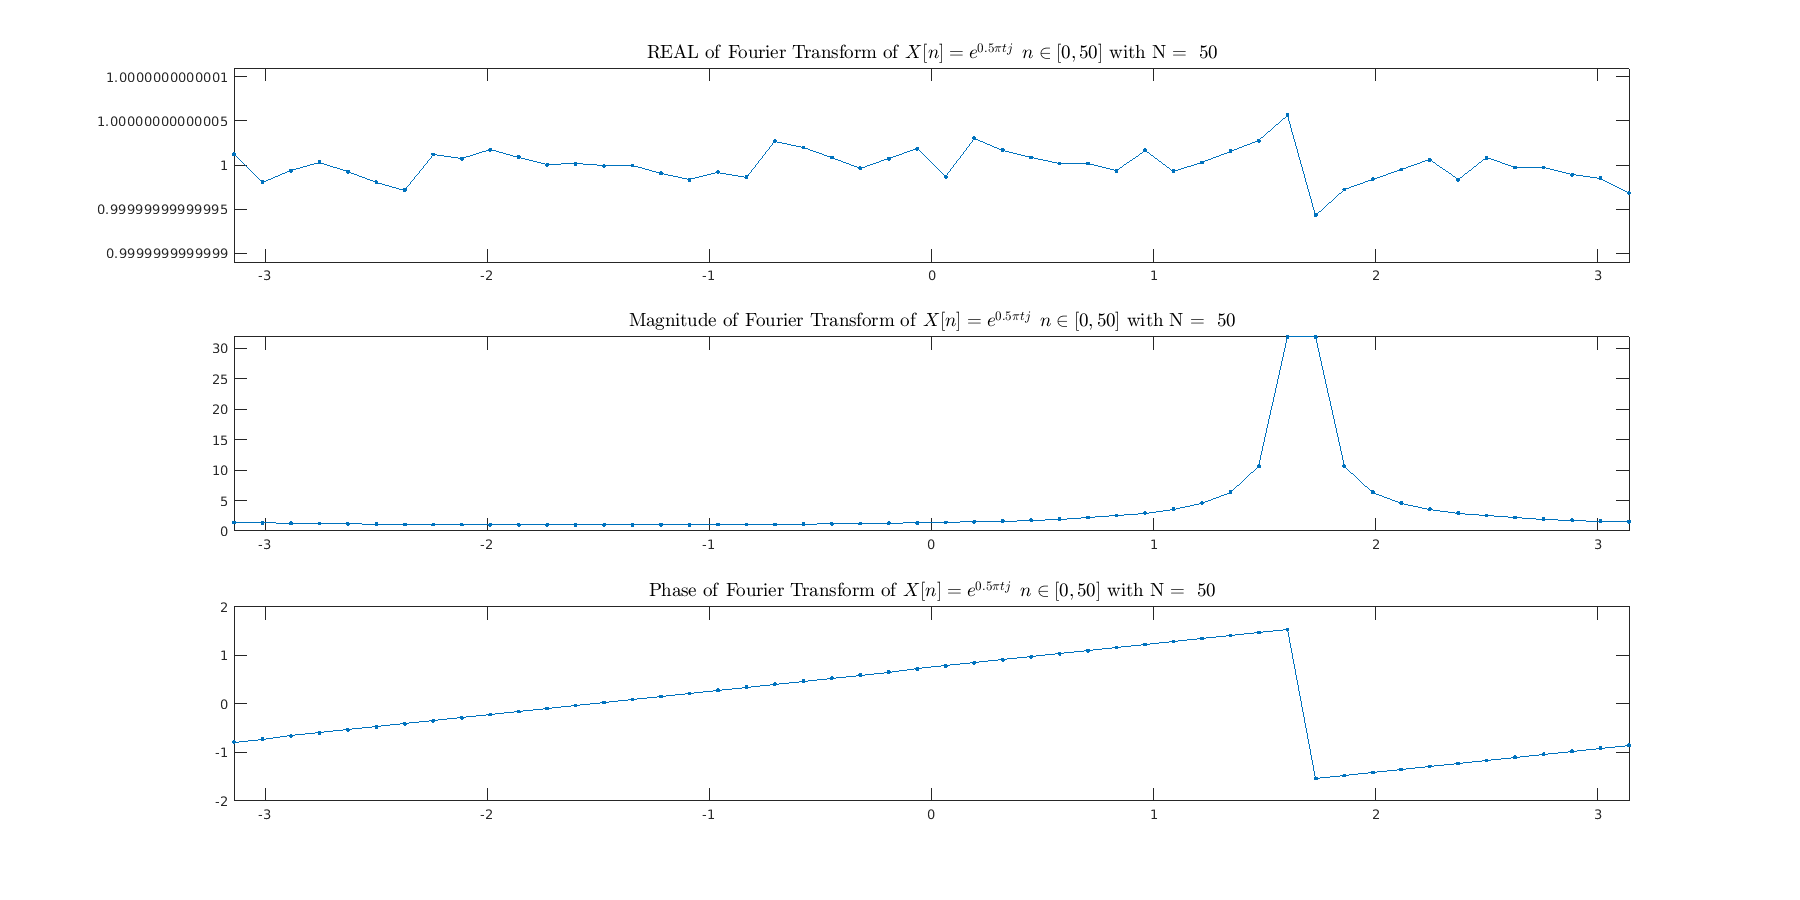

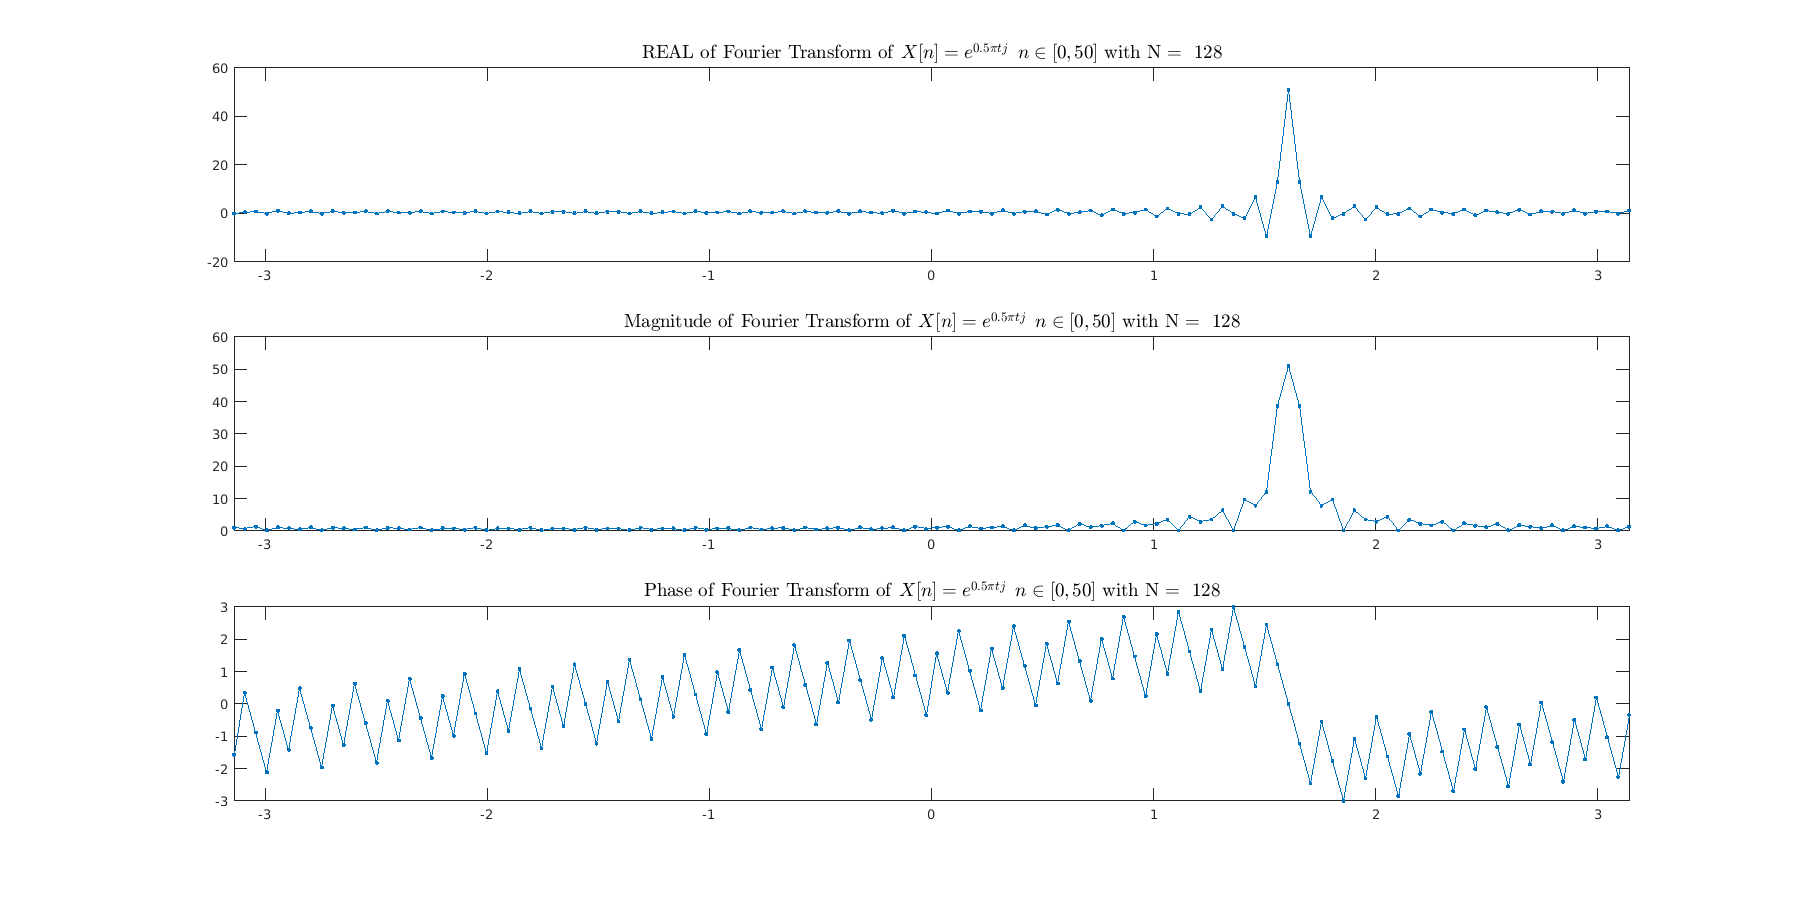

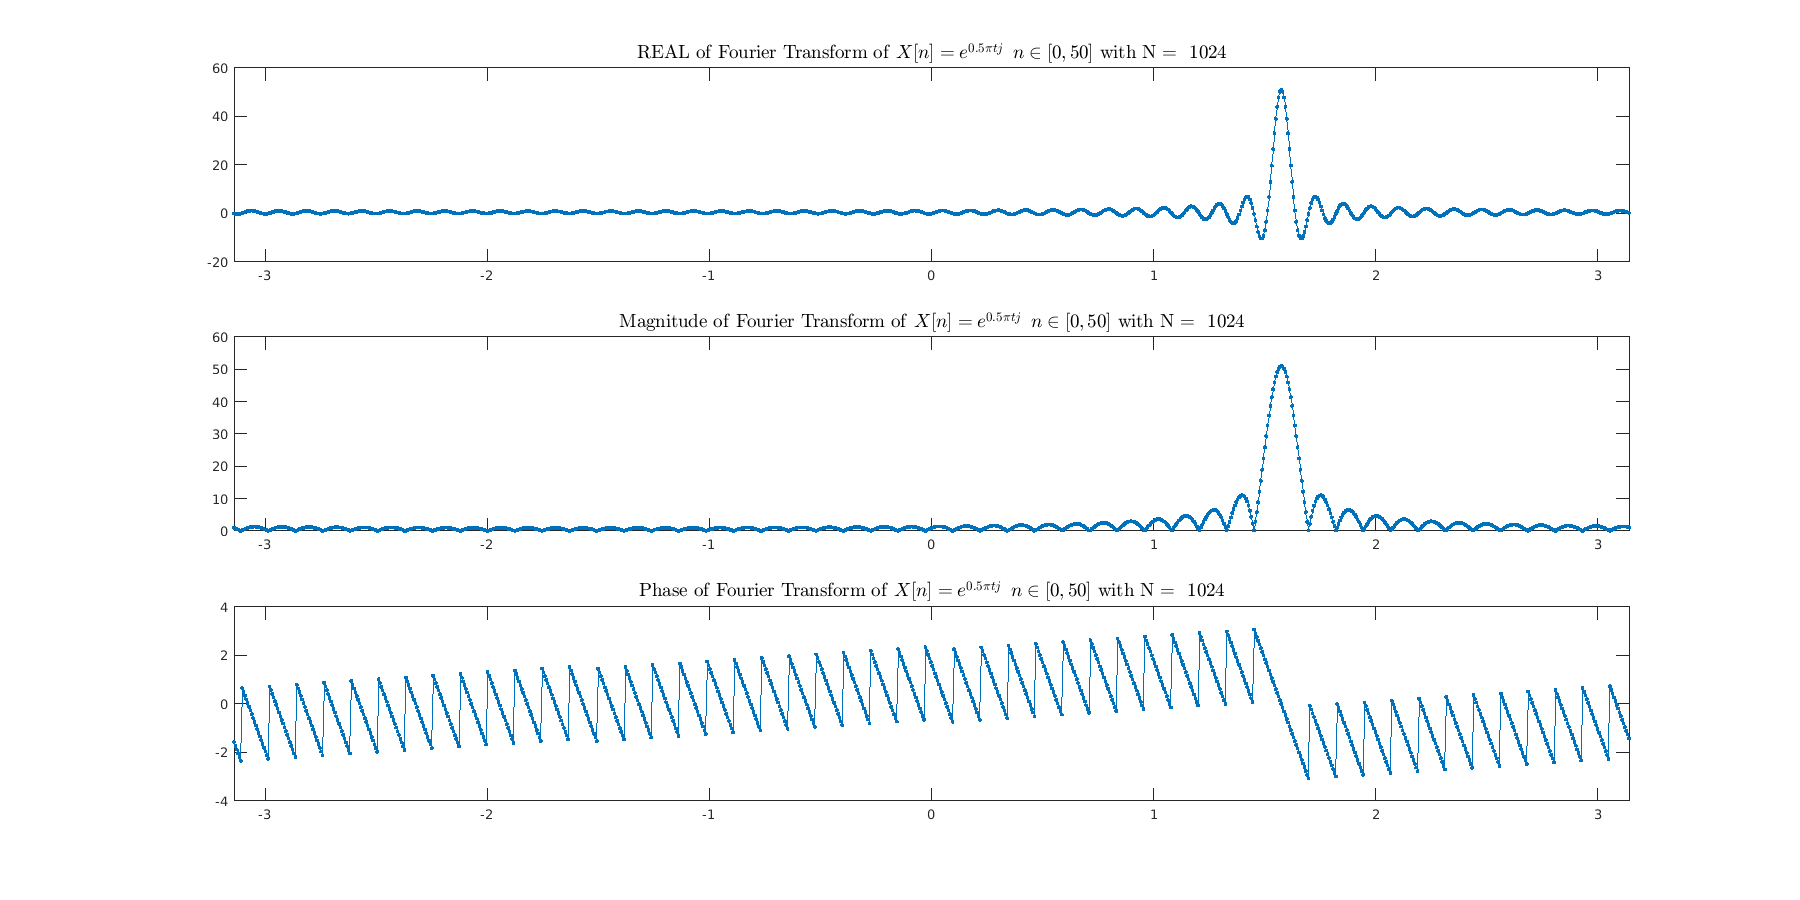

x = @(t) exp(0.5*pi .*t .* 1i) .* ((t<= 50) & (t>= 0));
clear title;
time_step =1;
t = 0:time_step:50;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1/time_step;
fft_repeat_plot(x(t),[50,128,1024]," $ X[n] = e^{0.5 \pi t j} \: \: n \in  [0,50] $ ")

## x4

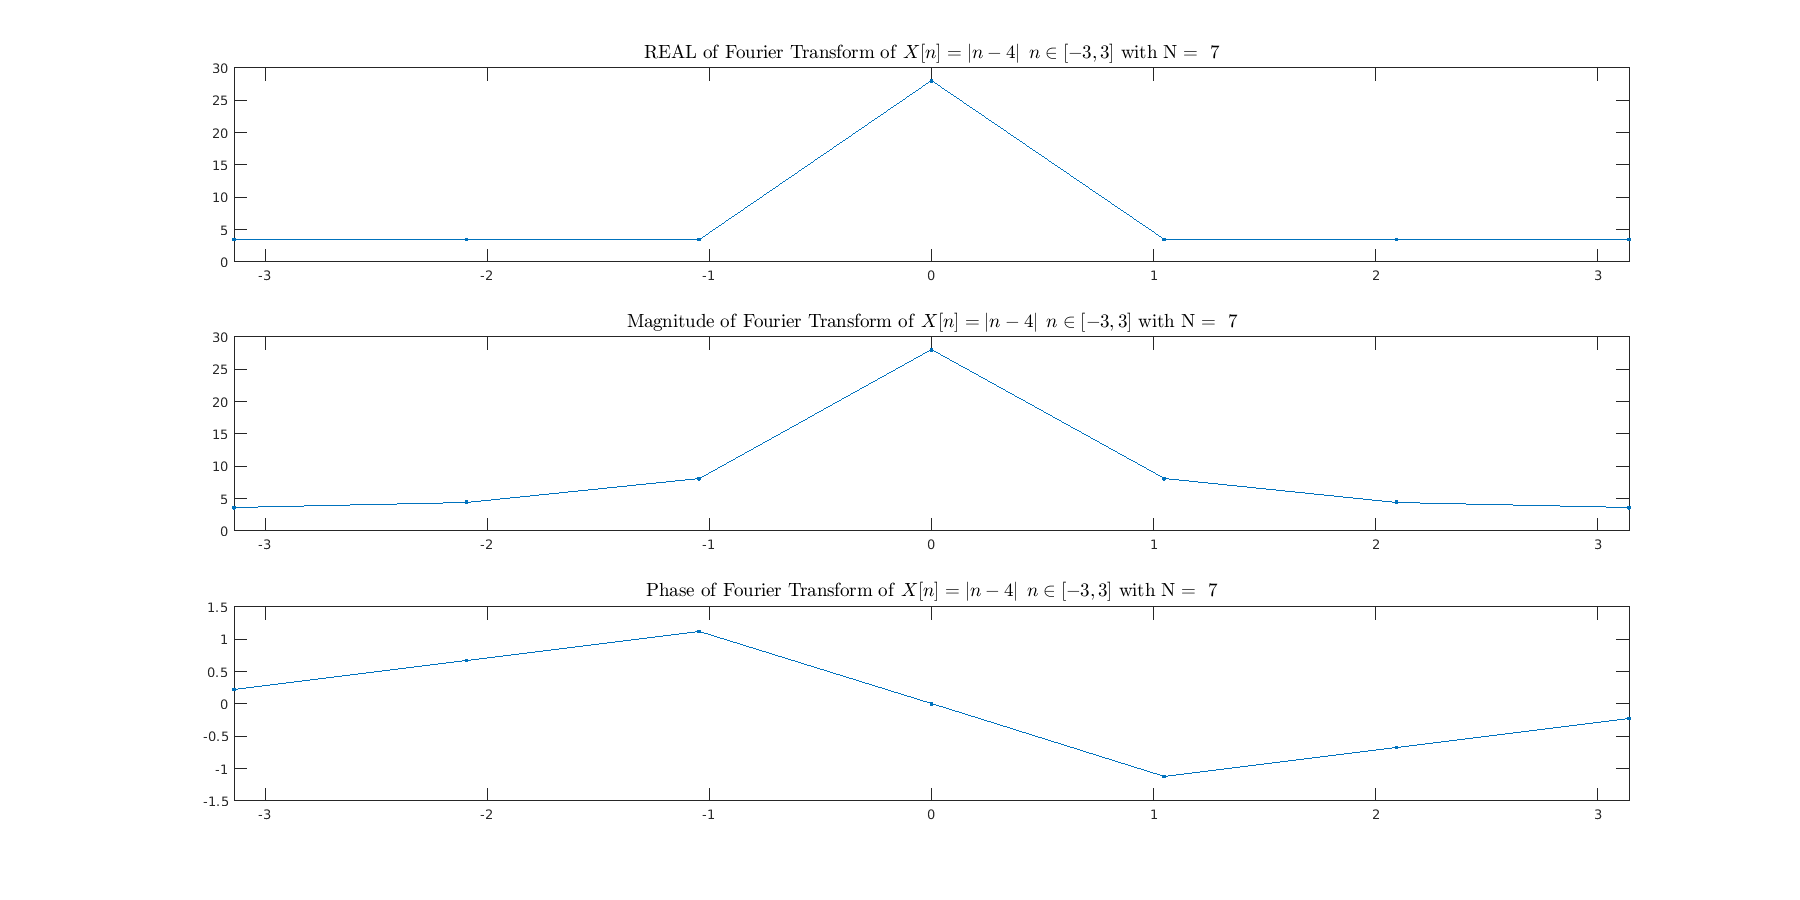

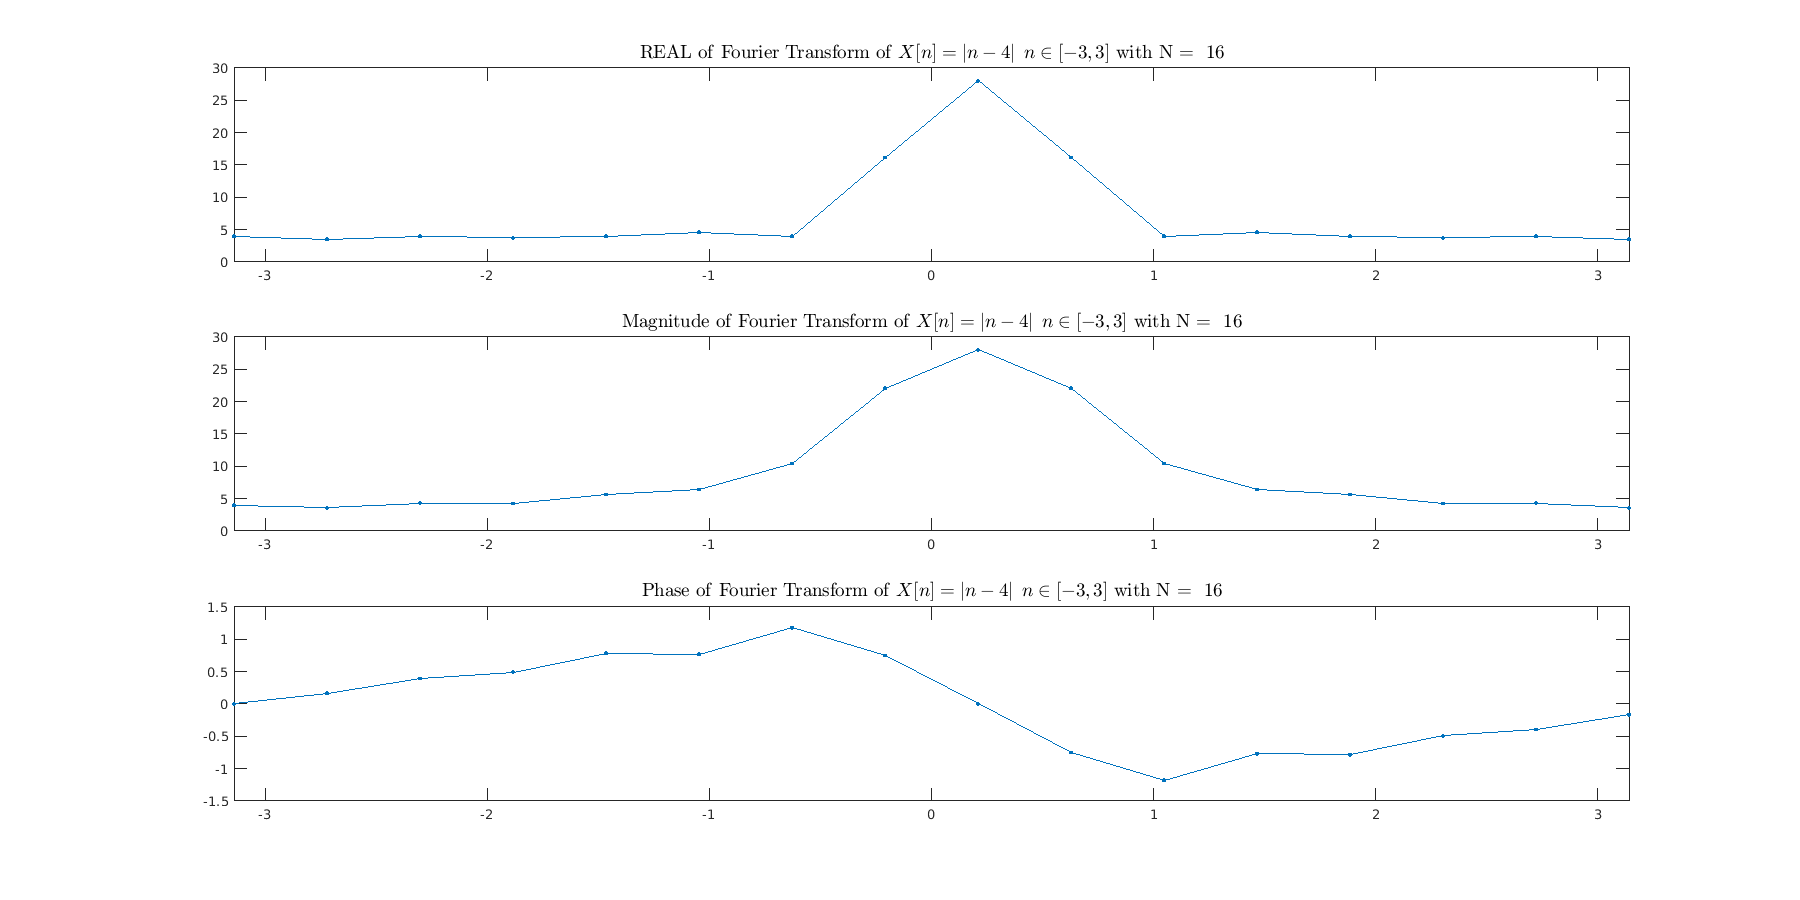

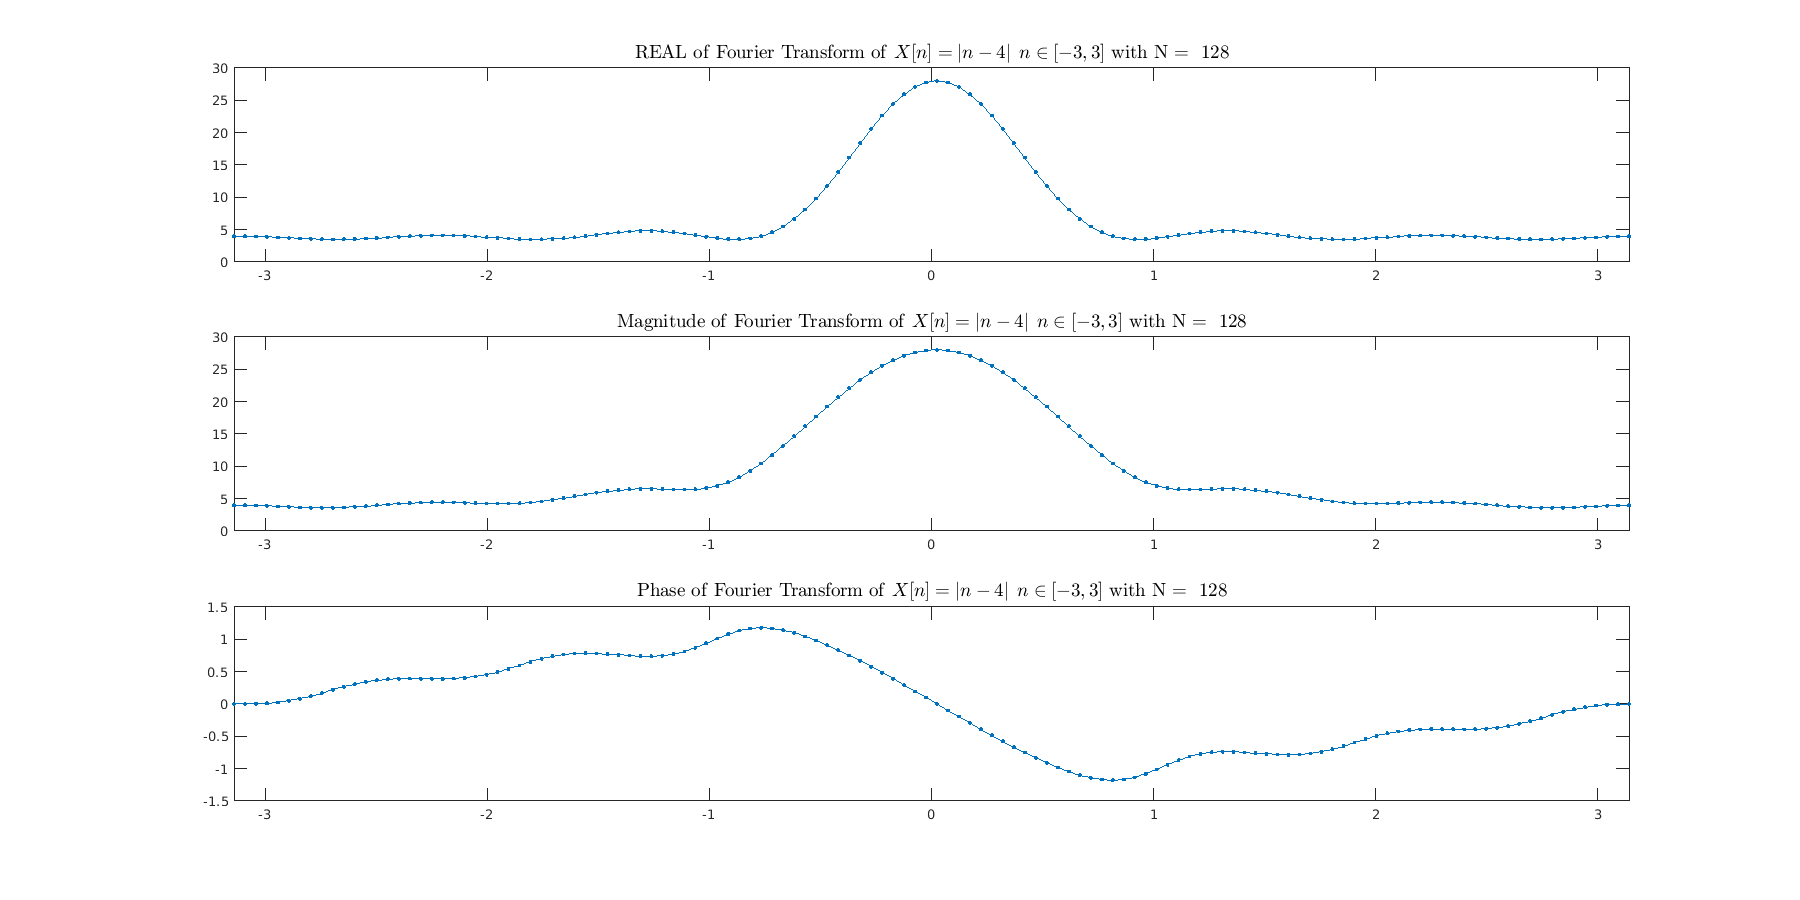

x = @(t) abs(t-4).* ((t<= 3) & (t>= -3));
clear title;
time_step =1;
t = -3:time_step:3;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1/time_step;
fft_repeat_plot(x(t),[7,16,128]," $ X[n] = |n-4| \: \: n \in  [-3,3] $ ")

## x5

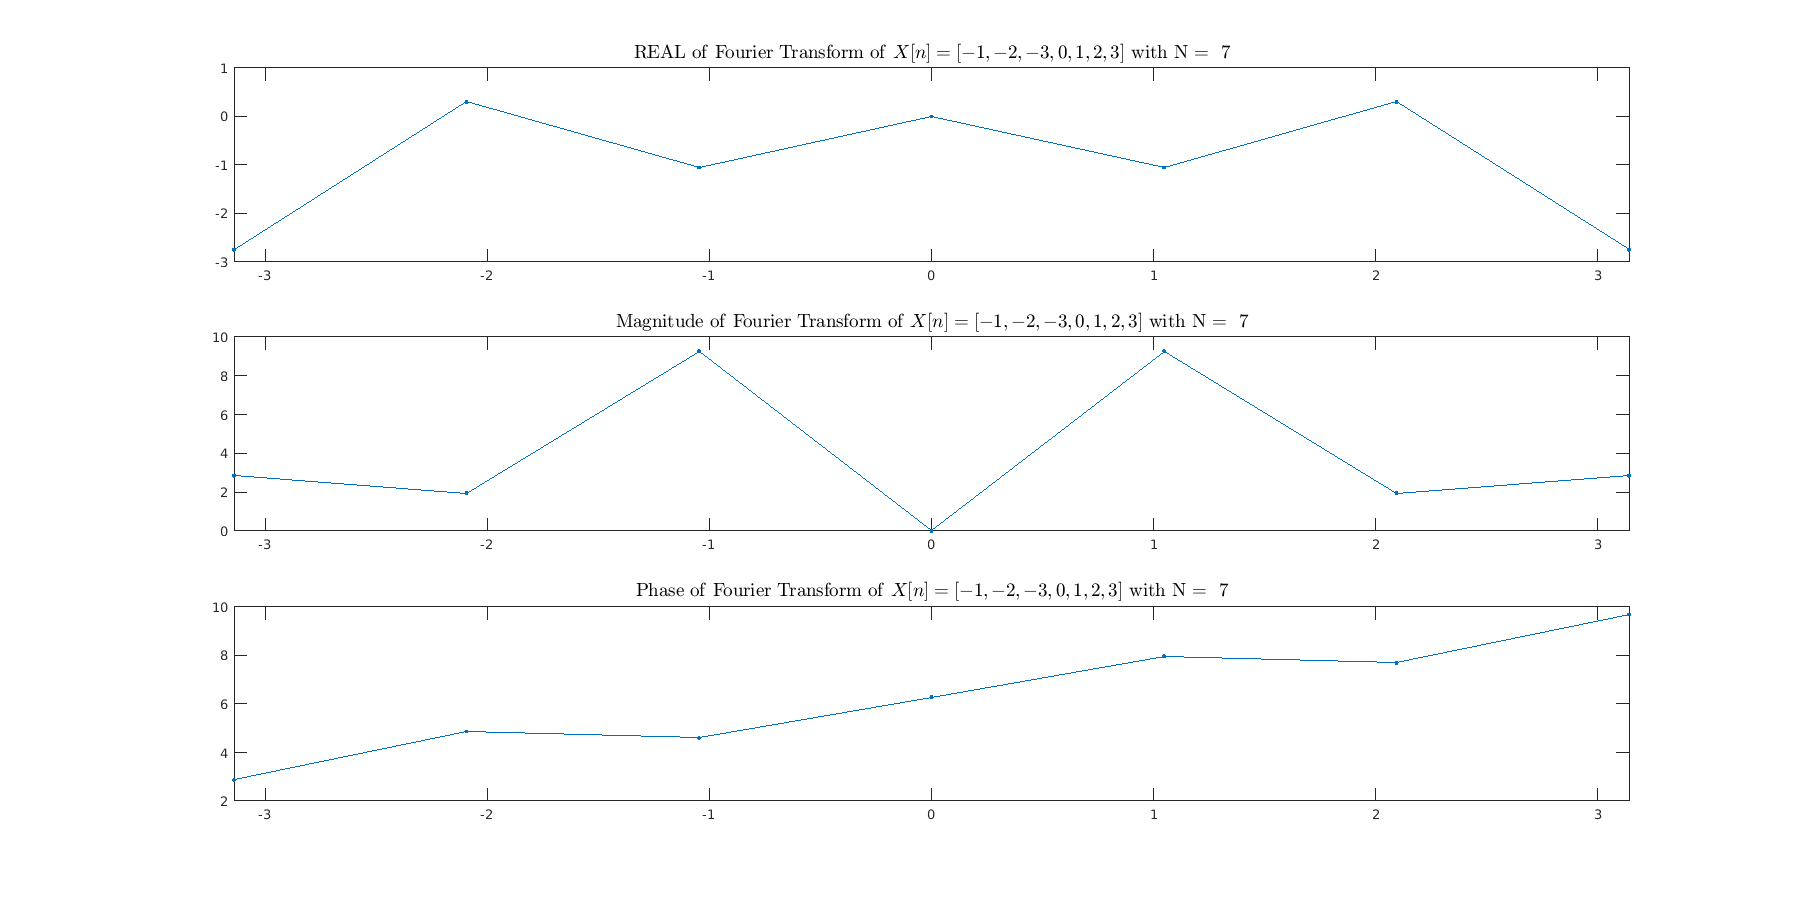

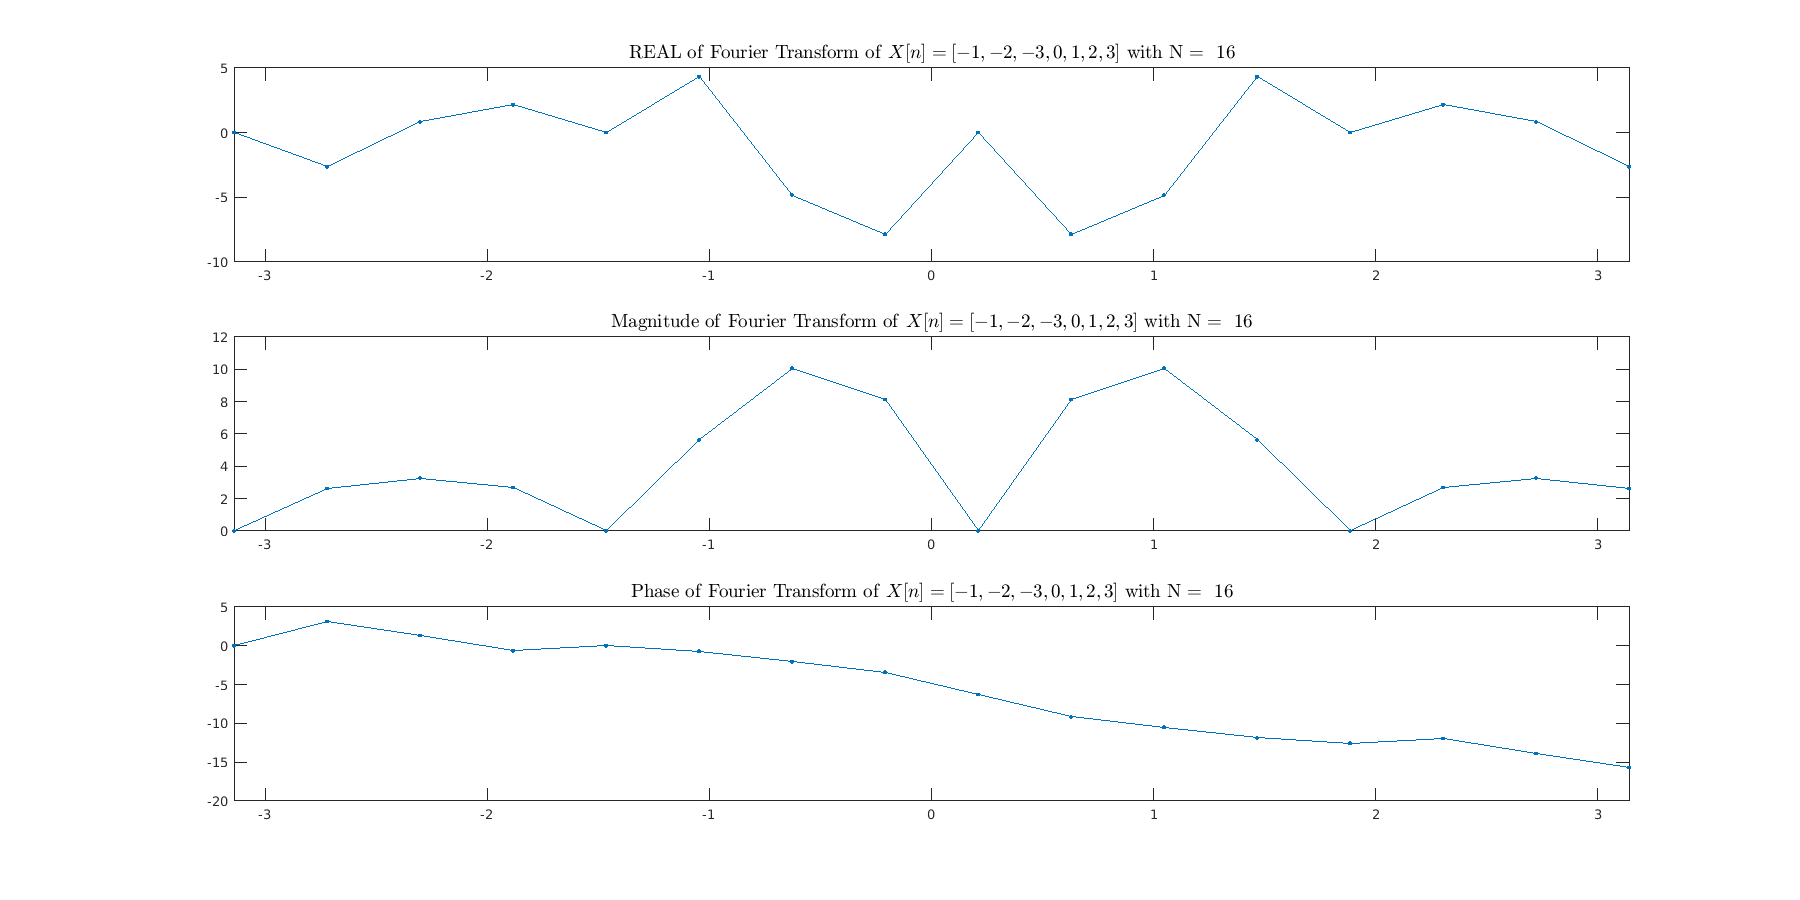

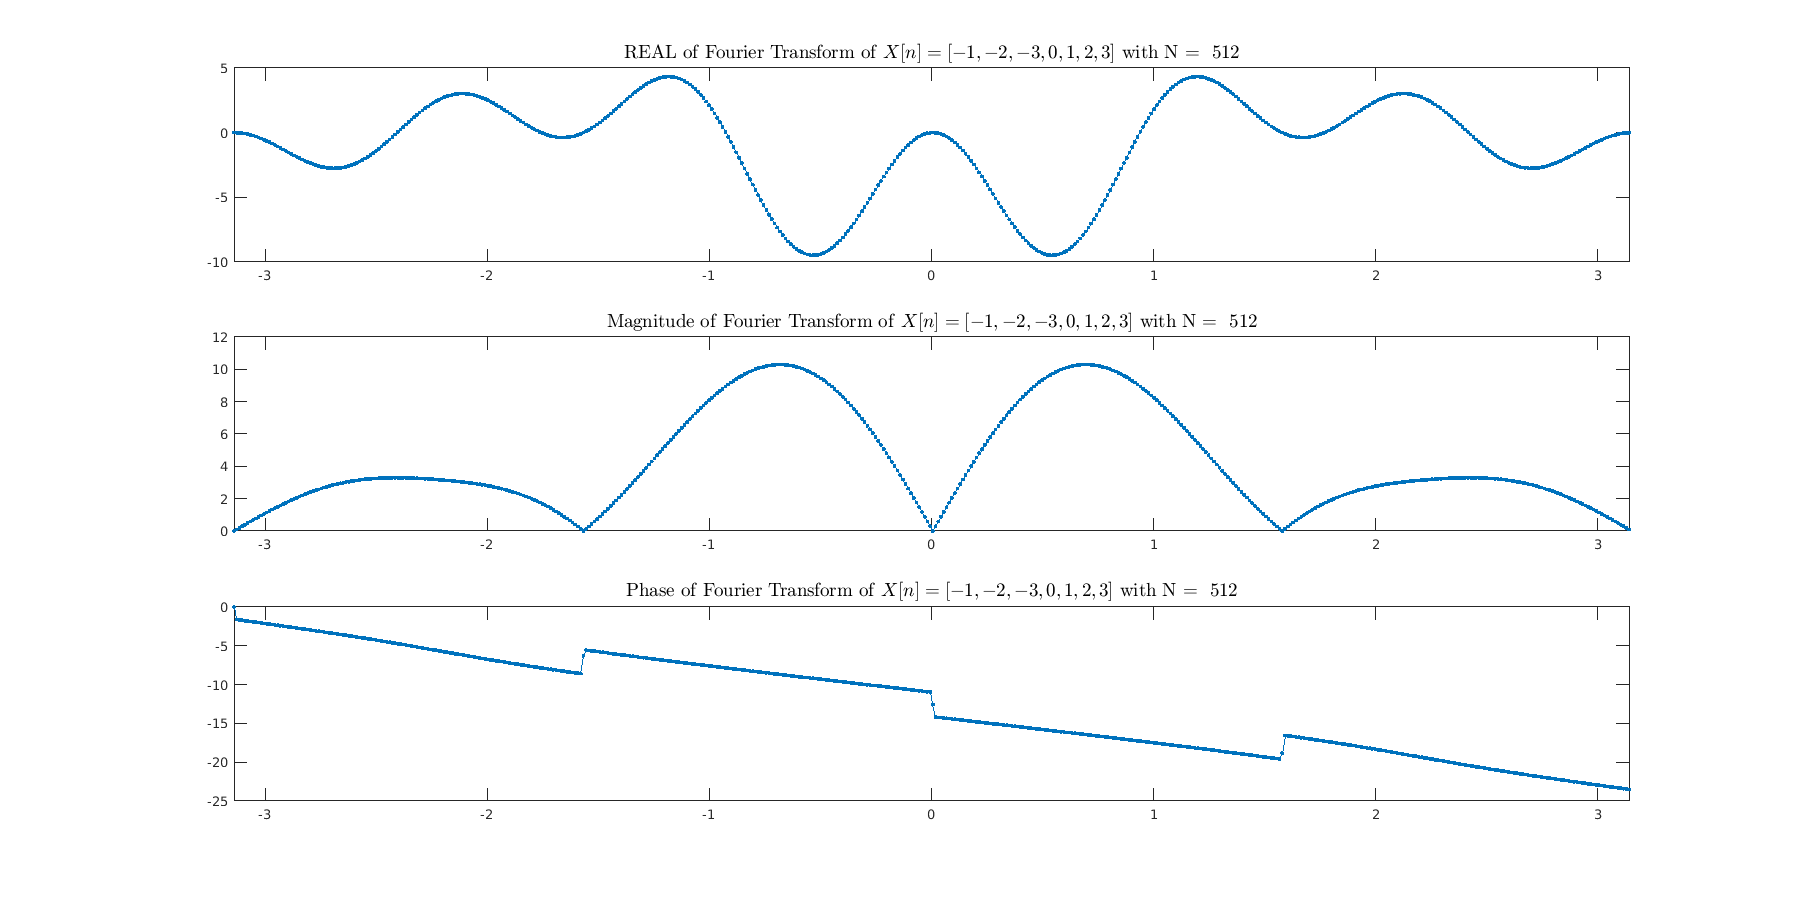

x = [-1,-2,-3,0,1,2,3];
clear title;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1;
fft_repeat_plot(x,[7,16,512]," $ X[n] = [-1,-2,-3,0,1,2,3] $ ")

# **part four**

X -> 0.9^n

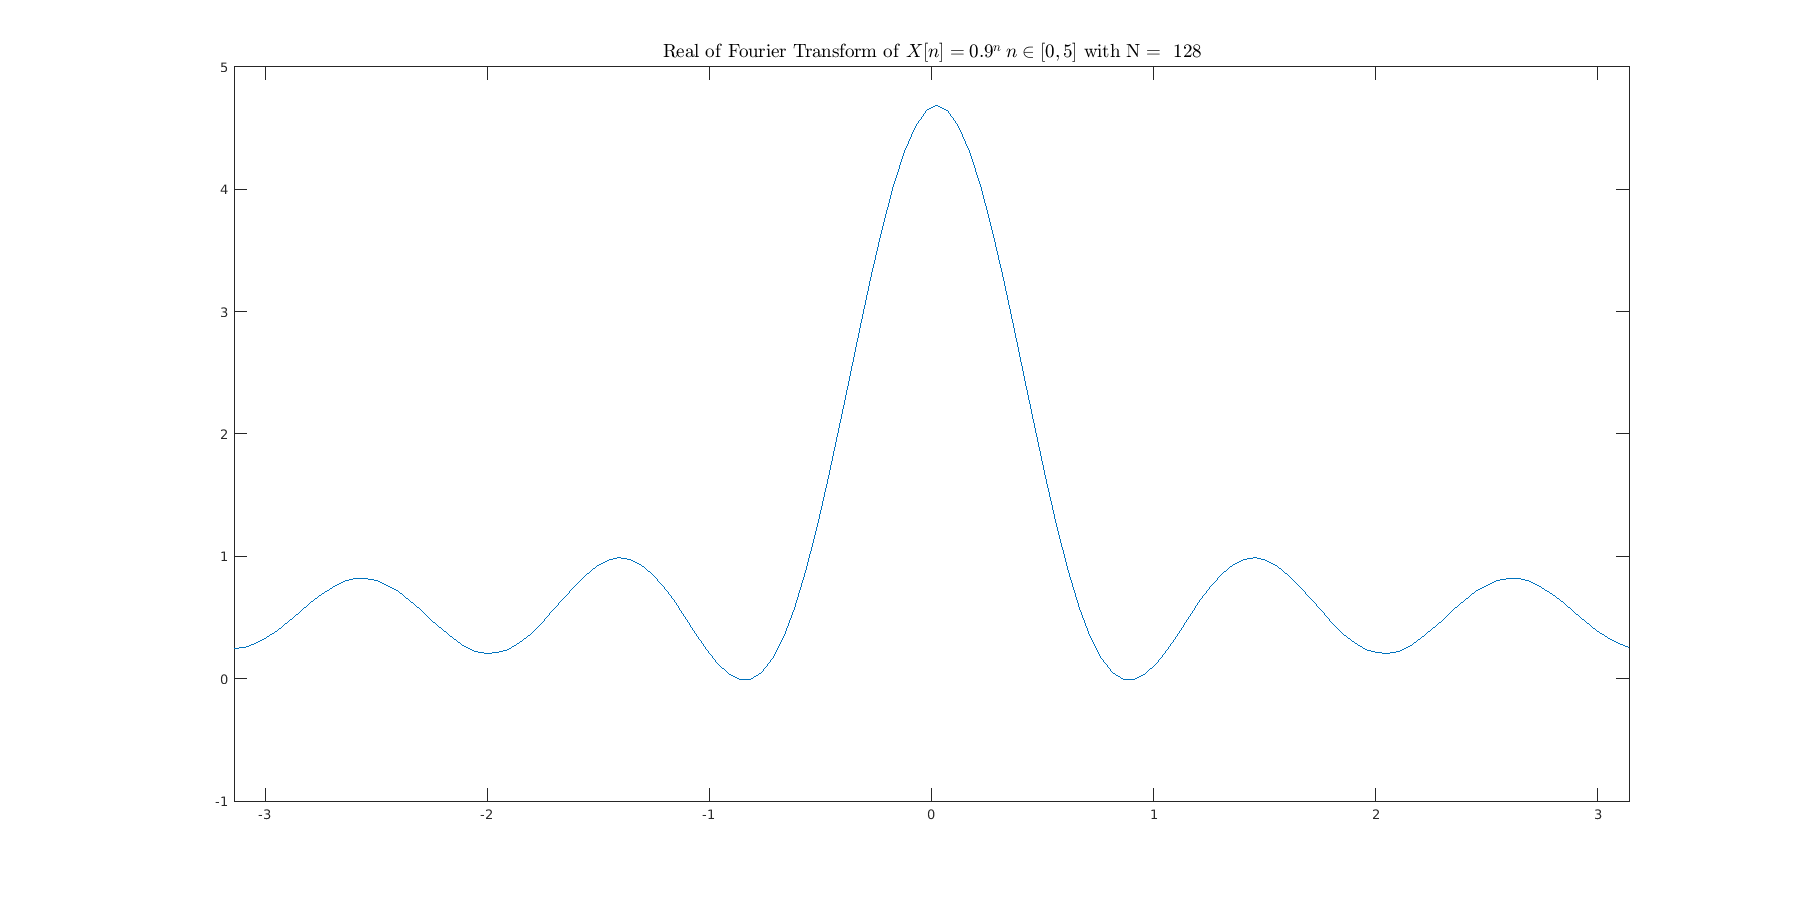

clear;
x = @(t) (0.9).^(t).* ((t<= 5) & (t>= 0));
clear title;
time_step =1;
t = 0:time_step:5;
figure;
set(gcf,'position',[0,0,1800,900])%,"visible","on")
fs = 1/time_step;
n = 128;
F = fftshift(fft(x(t),n));
f = linspace(-pi, pi, numel(F));
figure;
set(gcf,'position',[0,0,1800,900]);
plot(f,real(F))
title(strcat(strcat(strcat('Real\/ of\/ Fourier\/ Transform\/ of\/ '," $ X[n] = 0.9^n \: n \in [0,5] $ "),"with N = \/ "),string(n)),"fontsize",14,"interpreter","latex")
ax = gca;
xlim([-pi,pi])

plot the real part given

clear;
syms v k
G(v) = sum(subs((0.9) .^k .* cos(v*k),k,0:5))

$$G(v) = \frac{81\,\cos\left(2\,v\right)}{100}+\frac{729\,\cos\left(3\,v\right)}{1000}+\frac{6561\,\cos\left(4\,v\right)}{10000}+\frac{59049\,\cos\left(5\,v\right)}{100000}+\frac{9\,\cos\left(v\right)}{10}+1$$

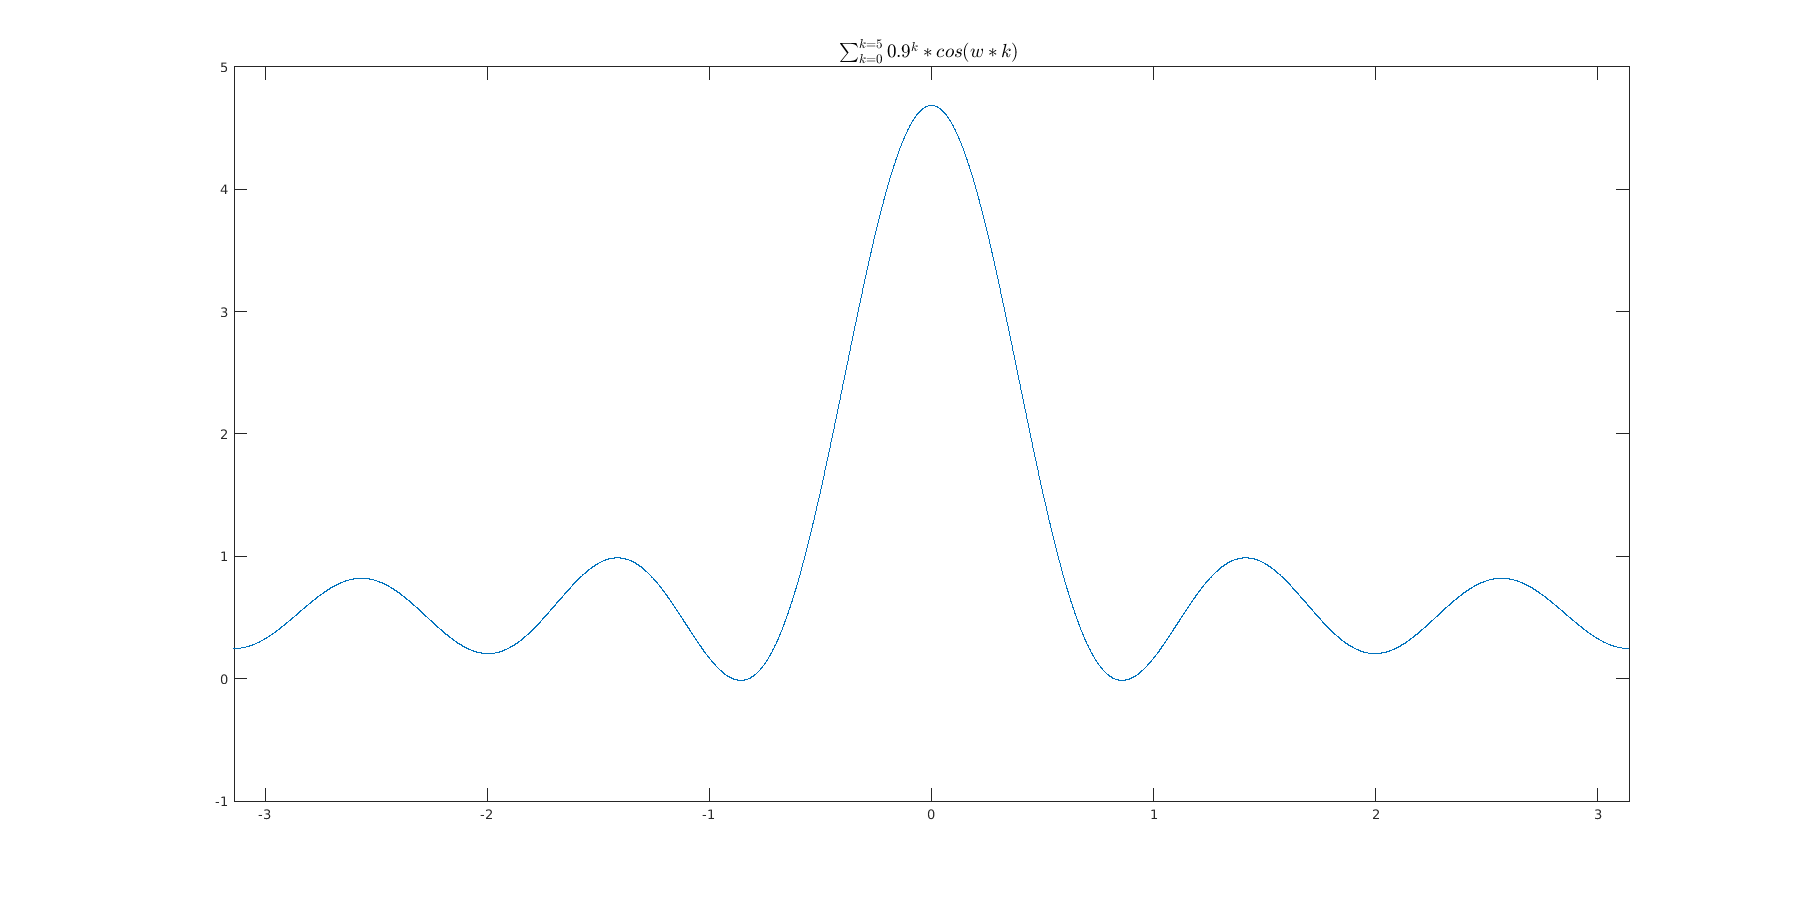

%x = @(t,w) cos(t*w) .* (0.9).^(t).* ((t<= 5) & (t>= 0));
%H = @(t,w) sum(x(t,w));
time_step =1;
t = 0:time_step:5;
time_step2 = 0.001;
%w = -0.5:time_step2:0.5;
w = -5:0.001:5;
figure;
set(gcf,'position',[0,0,1800,900]);
F = G(w);
plot(w,F)
title(strcat(strcat(strcat("  $\sum_{k=0}^{k=5} {0.9^k * cos(w*k) } $")," ")," " ),"fontsize",14,"interpreter","latex")
ax = gca;
xlim([-pi,pi])

# Test Theoretical part with matlab

%test1
clear;
w = -pi:0.01:pi;
syms x k
G(x) = sum(subs(exp(-1i .* x .* k),k,0:3));
x = G(w);
fft_test_plot(w,x,[-pi,pi],[-pi,pi]);

%test2
alpha = 1/(exp(0.9));
G = @(x) (1-alpha^2) ./ (1+alpha^2 -2 * alpha .* cos(x));
x = G(w);
syms y
F =@(y) sin(5.5 .* y) ./ sin(y/2);
Y = F(w);
g = conv(Y,x,'same');
fft_test_plot(w,g,[-pi,pi],[-pi,pi]);

shg;
x = @(t) 2*exp(-0.9 .* abs(t)).* ((t<= 5) & (t>= -5));
time_step =1;
t = -5:time_step:5;
yfft = fftshift(fft(x(t)));
f = linspace(-pi, pi, numel(yfft));
plot(f,unwrap(angle(yfft)), '.-', 'markersize', 10);
xlim([-pi,pi]);
